s0_add_paths
viz = ColorPalette();

## NCE2 and OTS: Do the OTS filters really matter?

The answer might be: NO! 

NCE2 and OTS are similar

- Evidence 1: the smulations : see the OTSFilters.m 

- Evidence 2: the R2: show the R2 table

- Evidence 3: the predictions: 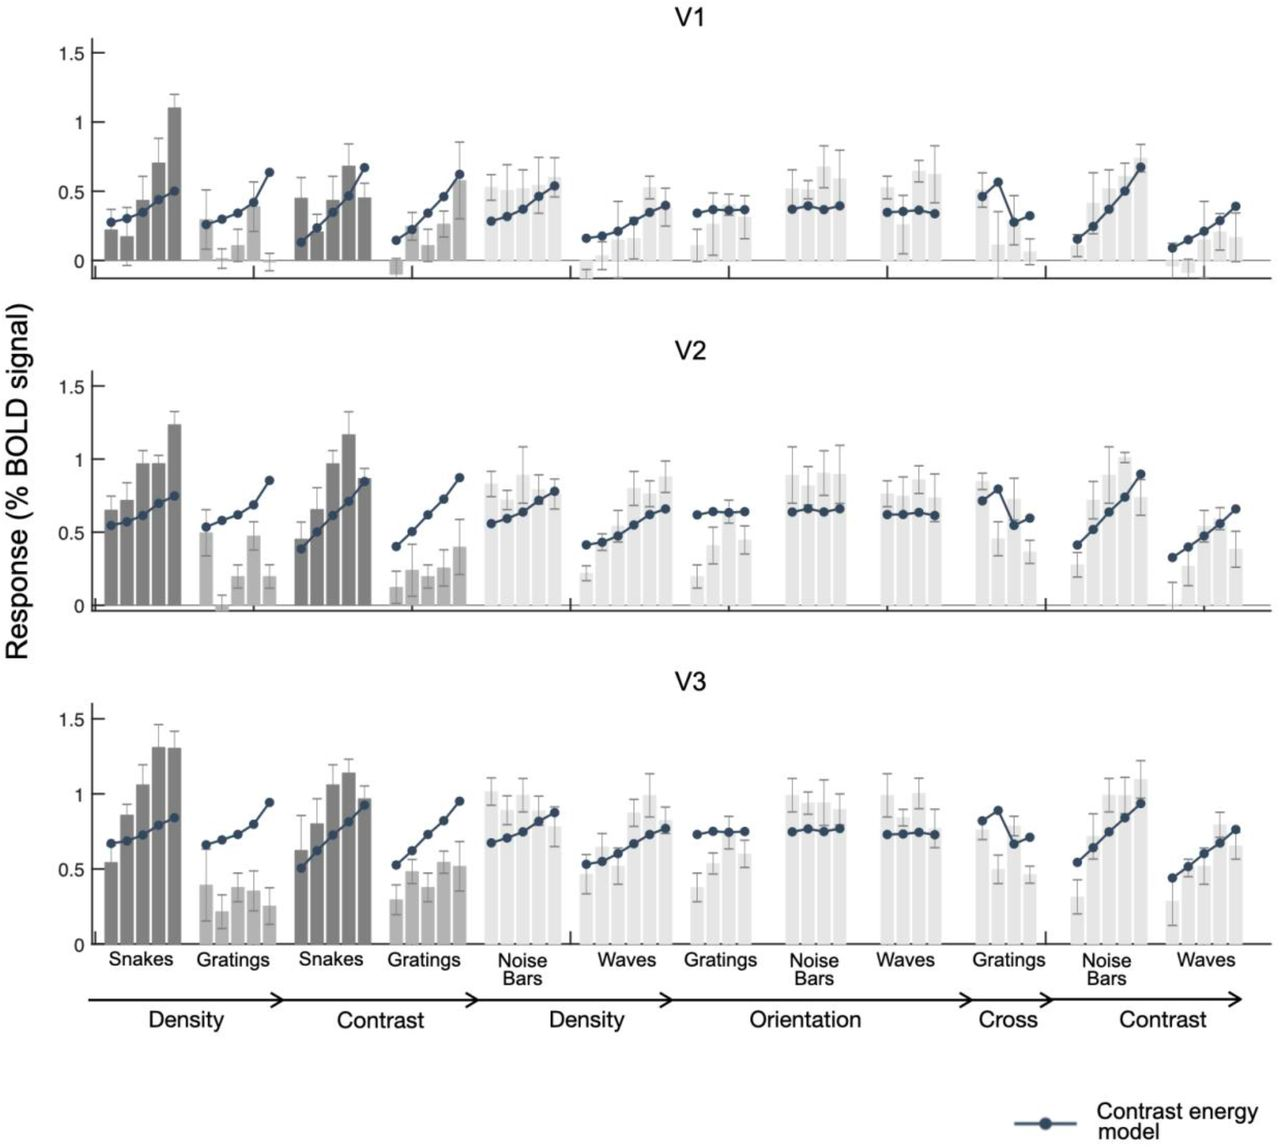

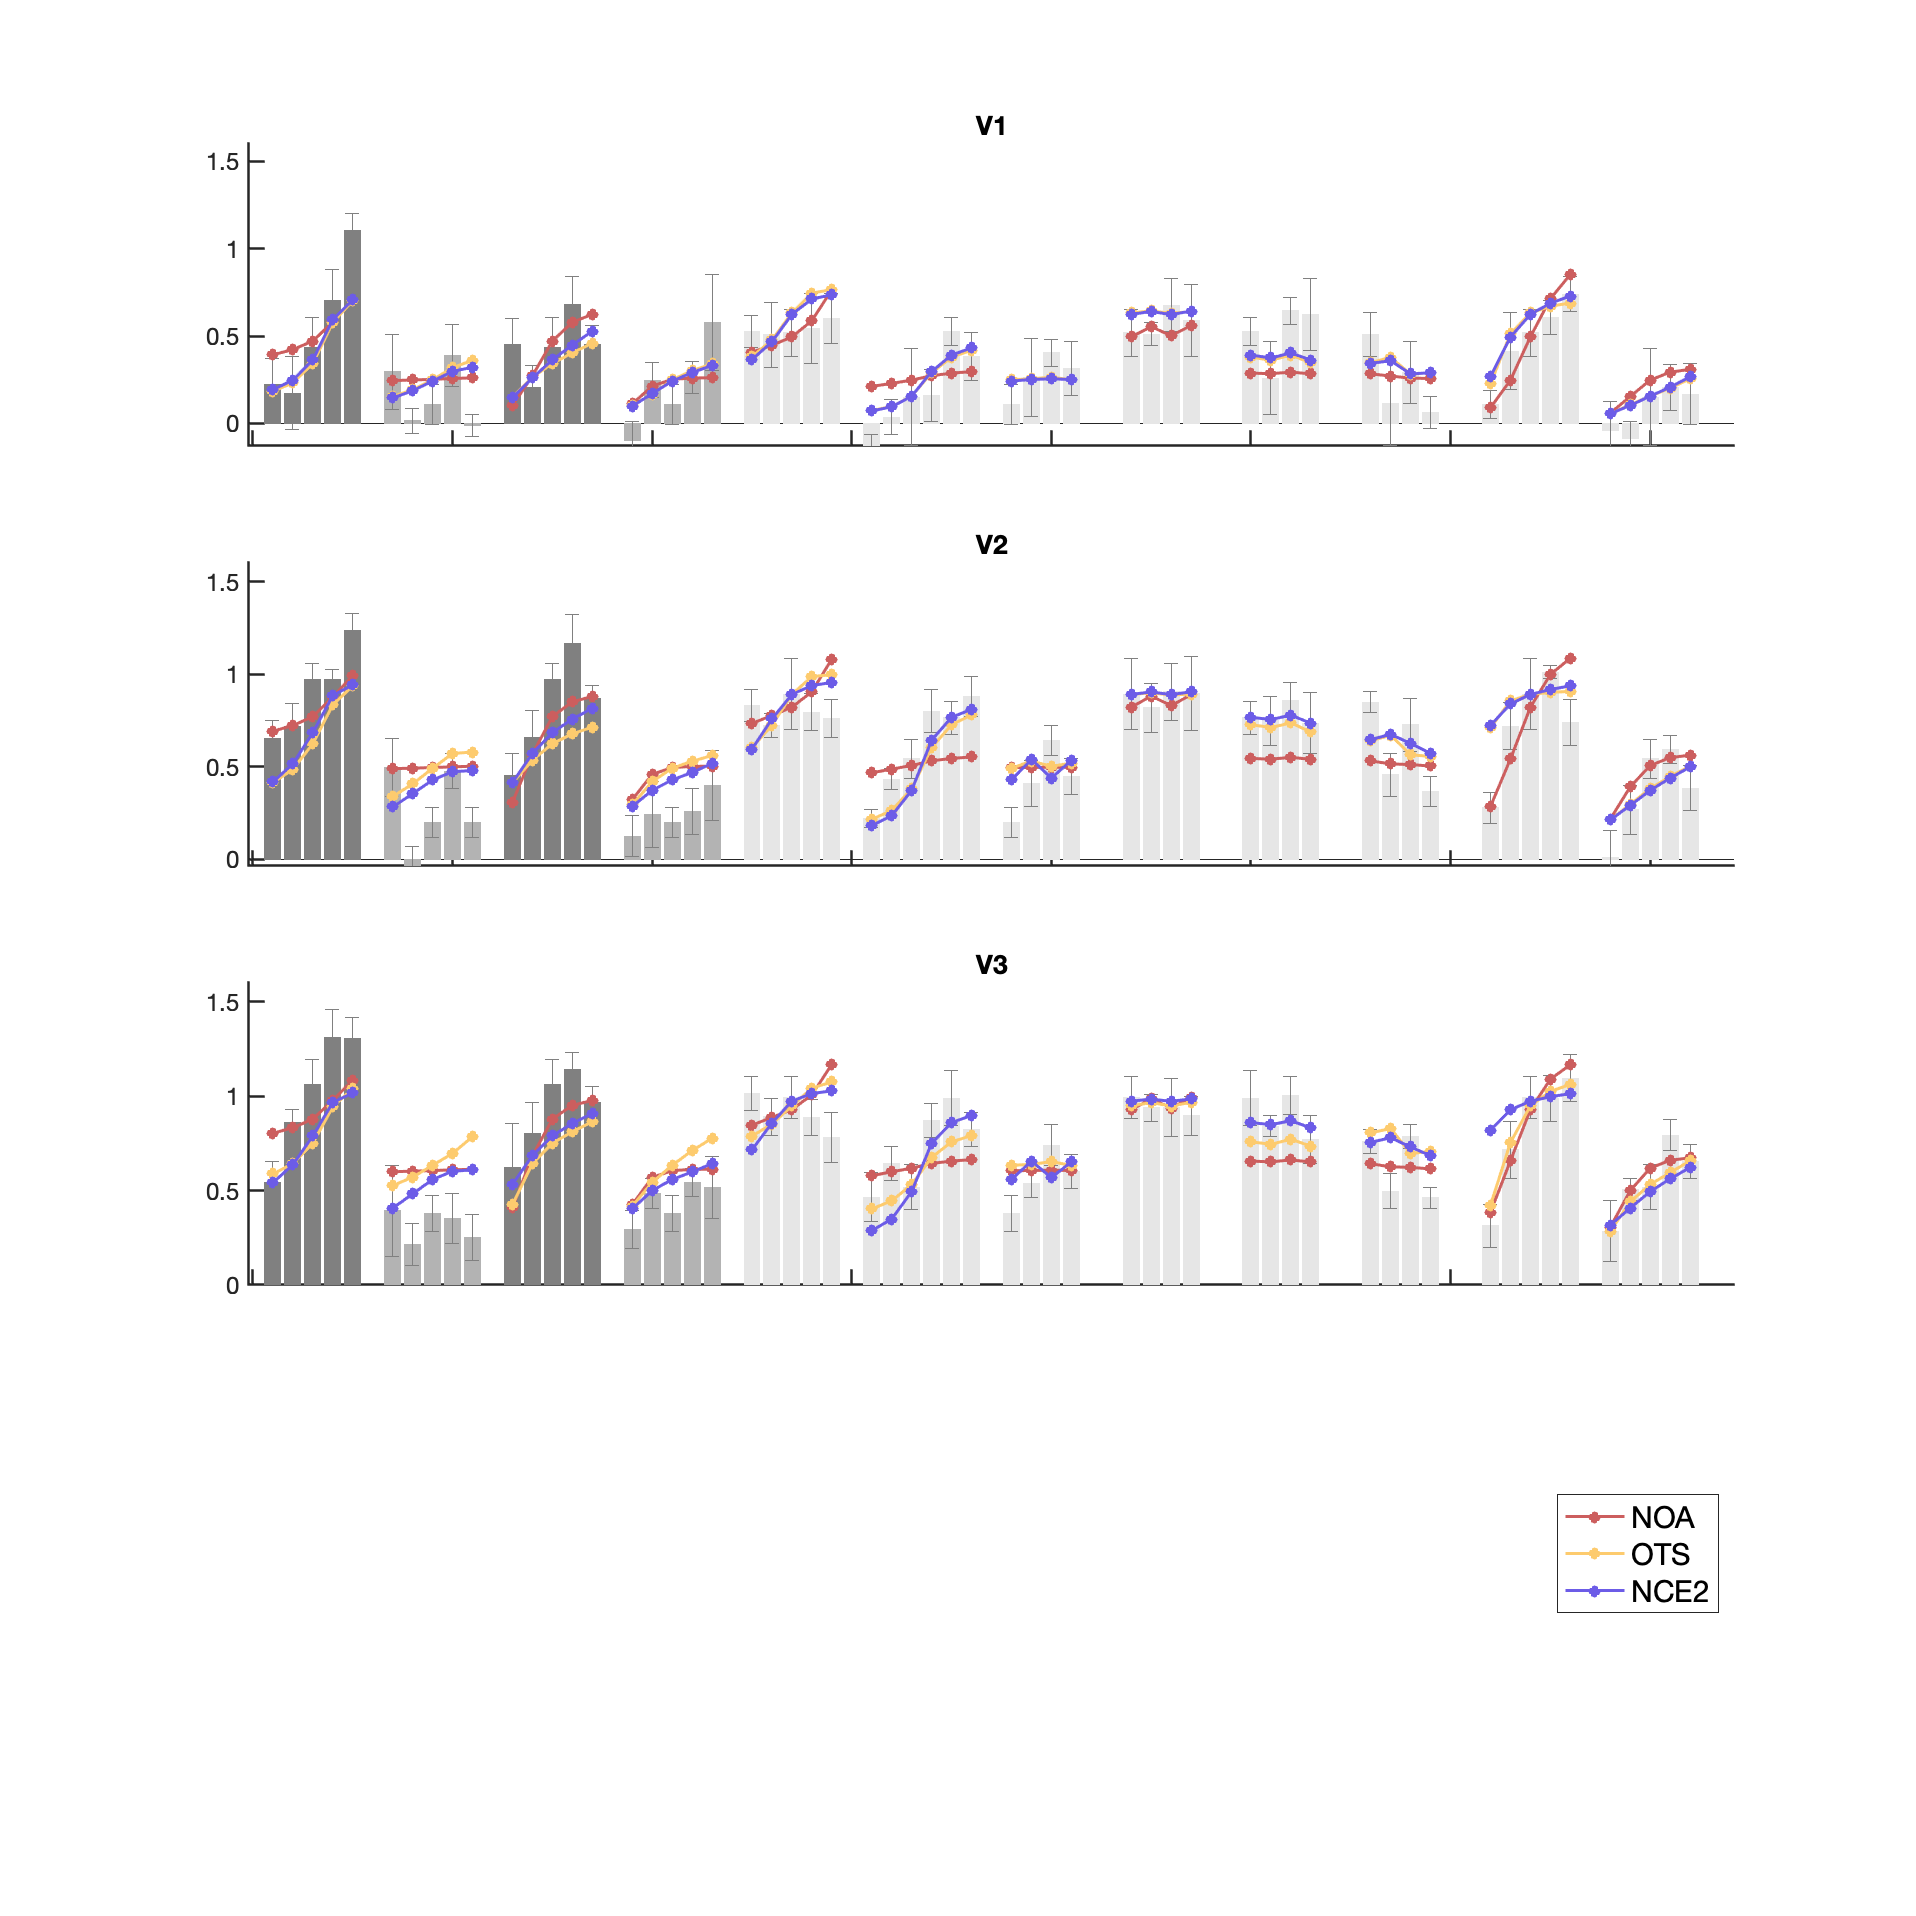

figure();

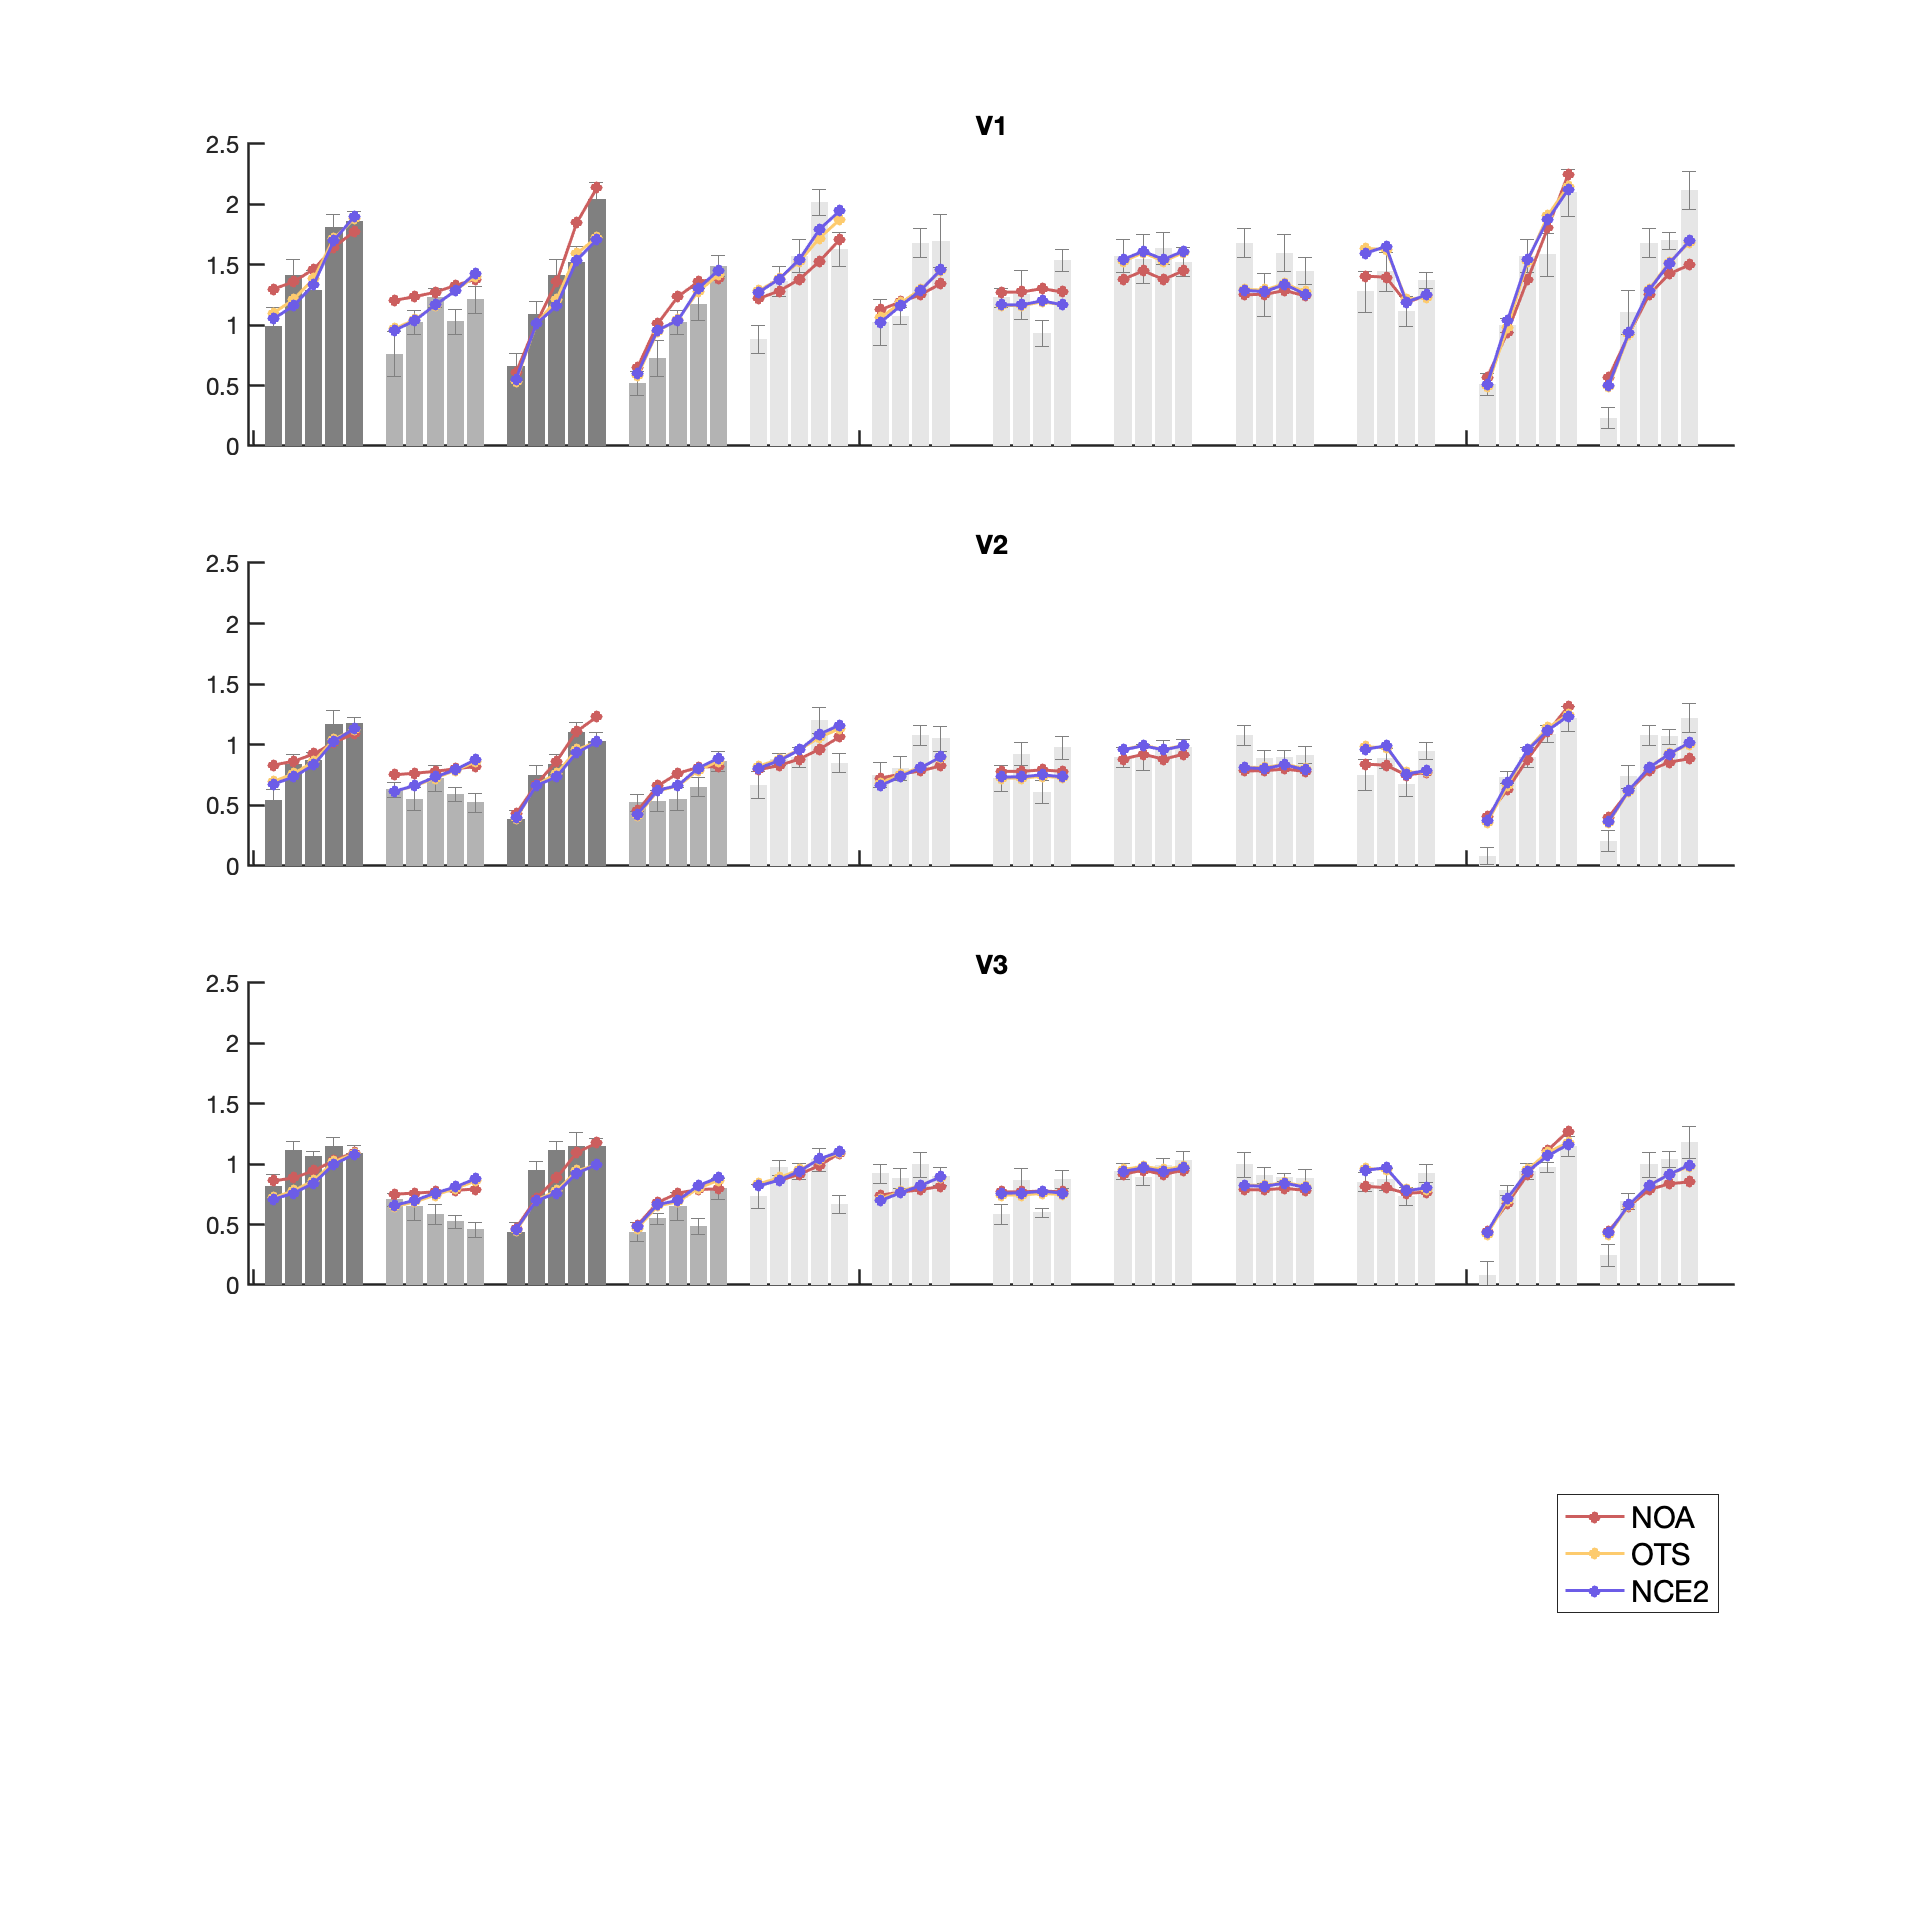

s4_visualize('all-noCross-m3m5m6-ds1');
figure();

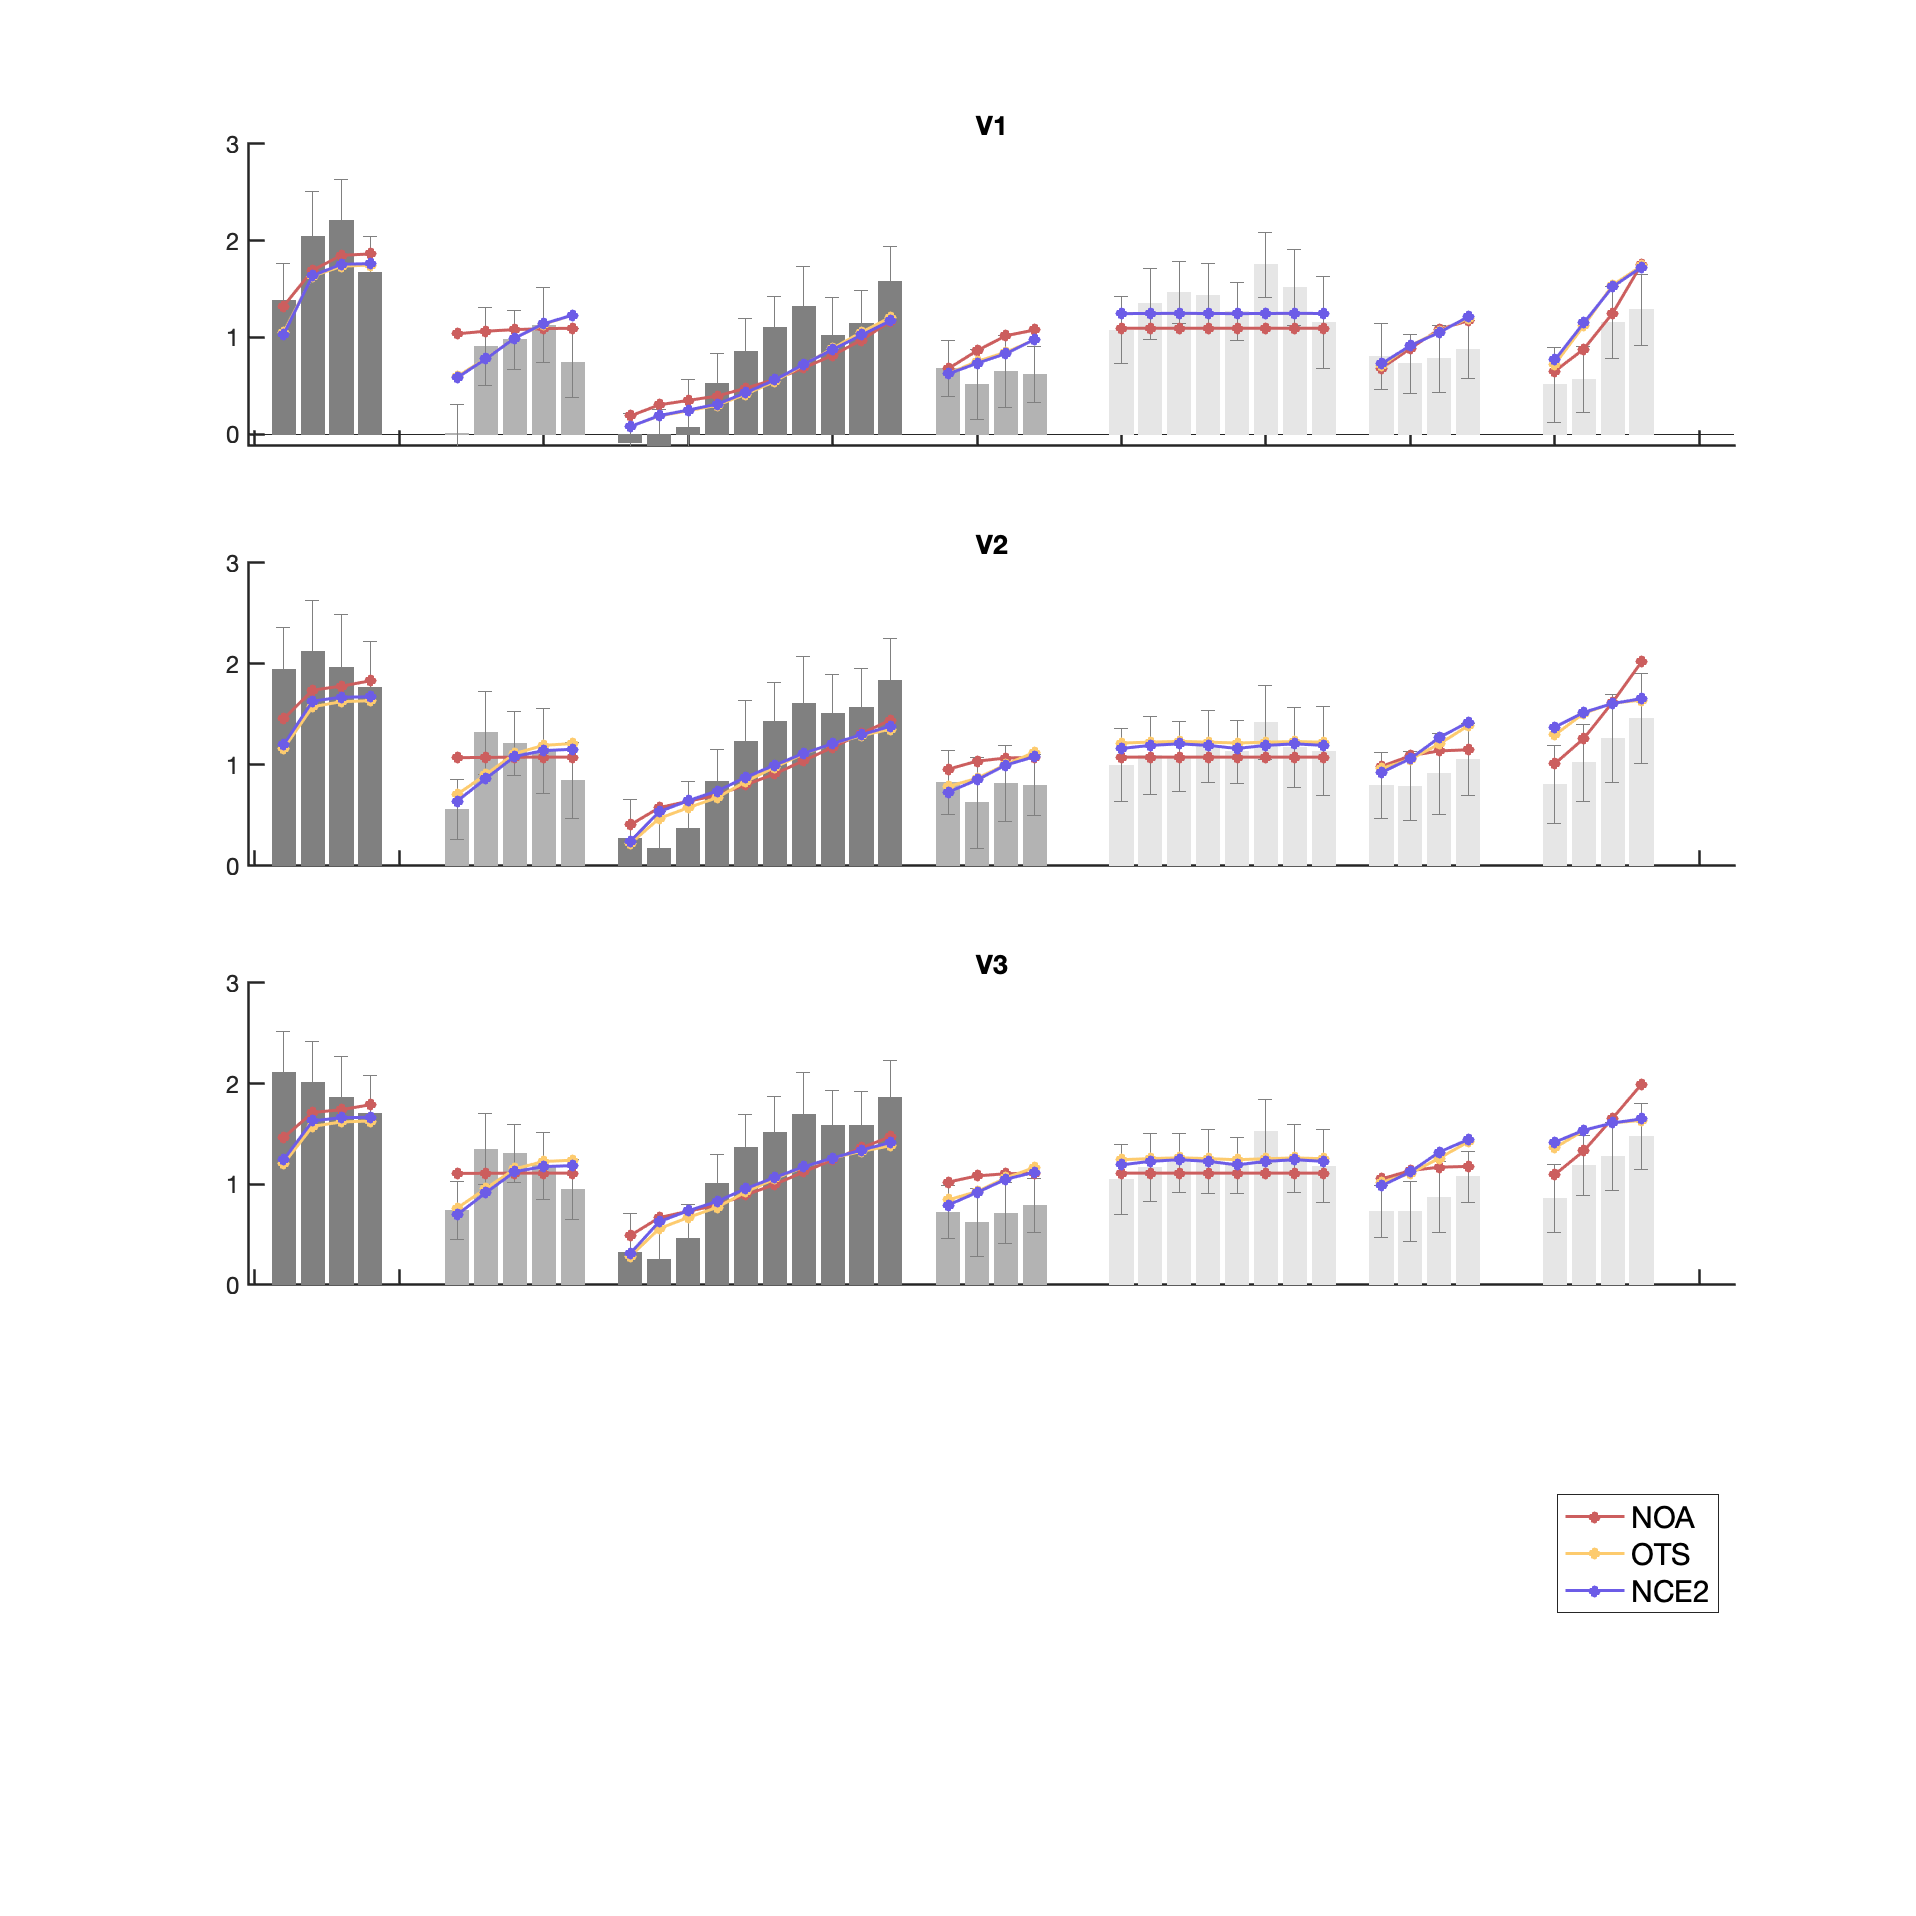

s4_visualize('all-noCross-m3m5m6-ds2');
figure();

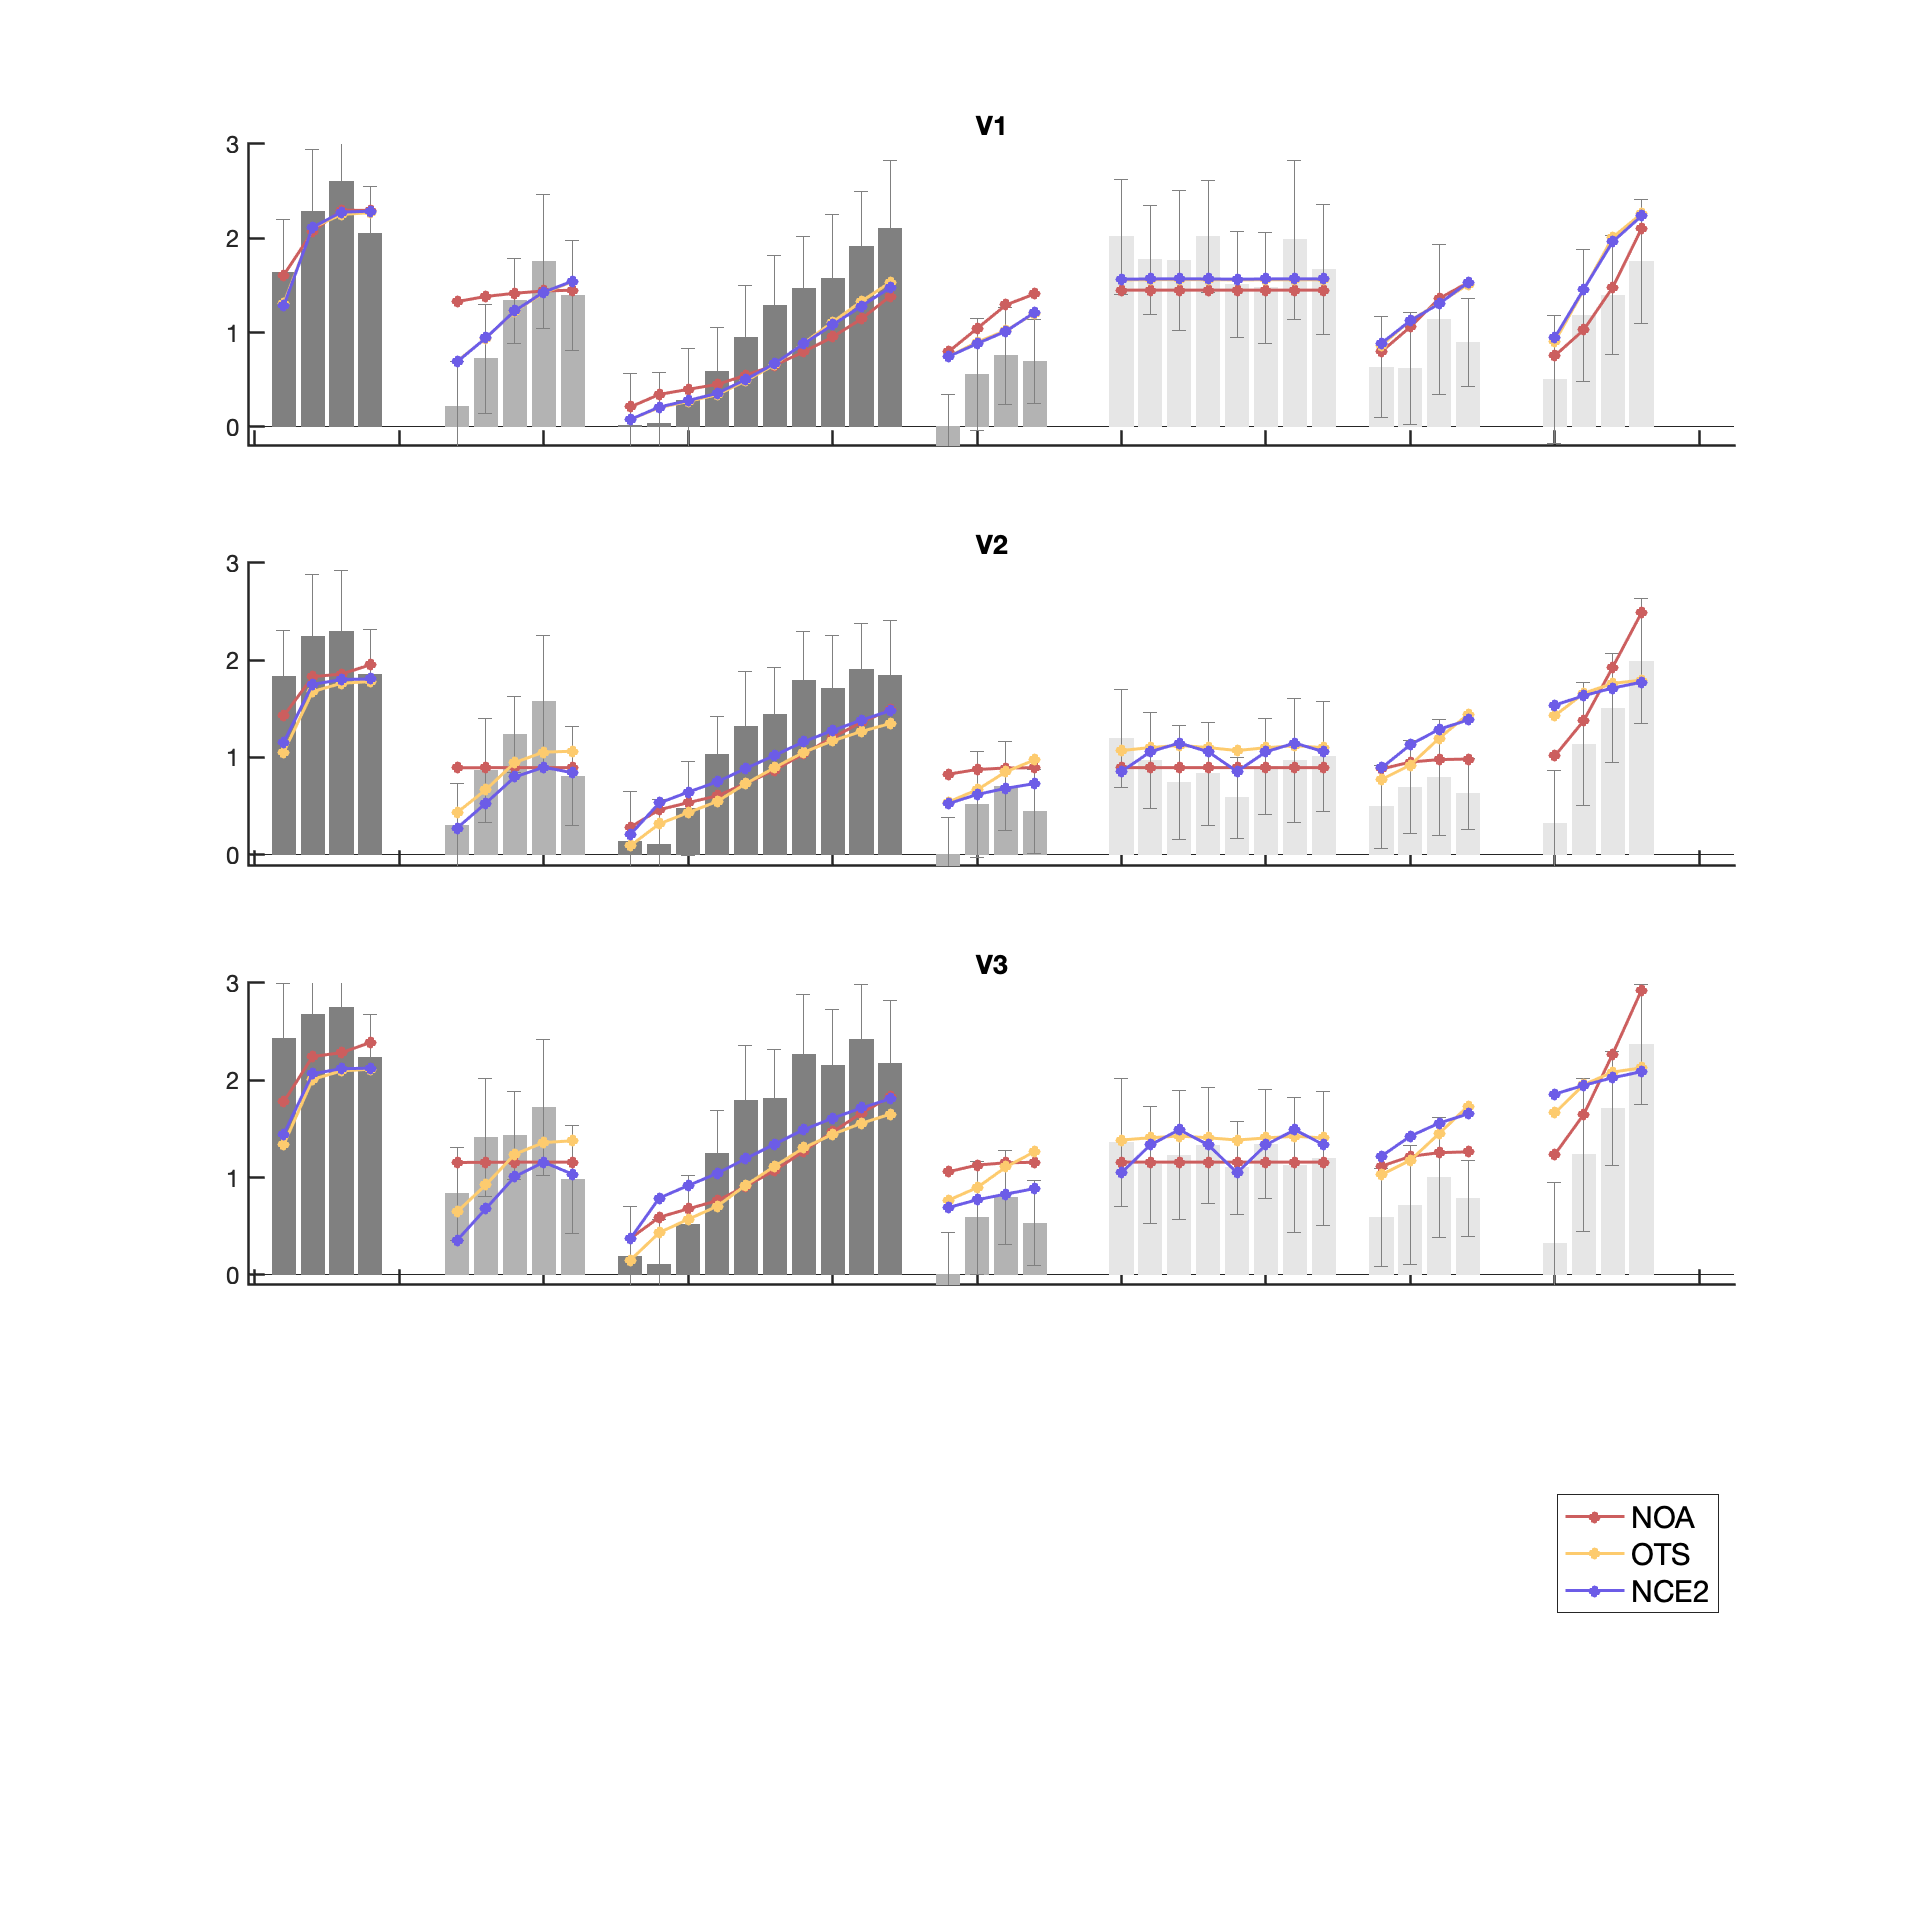

s4_visualize('all-noCross-m3m5m6-ds3');
figure();

s4_visualize('all-noCross-m3m5m6-ds4');

## Why the NCE works? 

First we generate two vectors:

E_Snake = [1/8, ....1/8] 

E_Grating = [h/8, ..., 1-7*h/8, h/8]

h here controls the degree of heterogenity. 

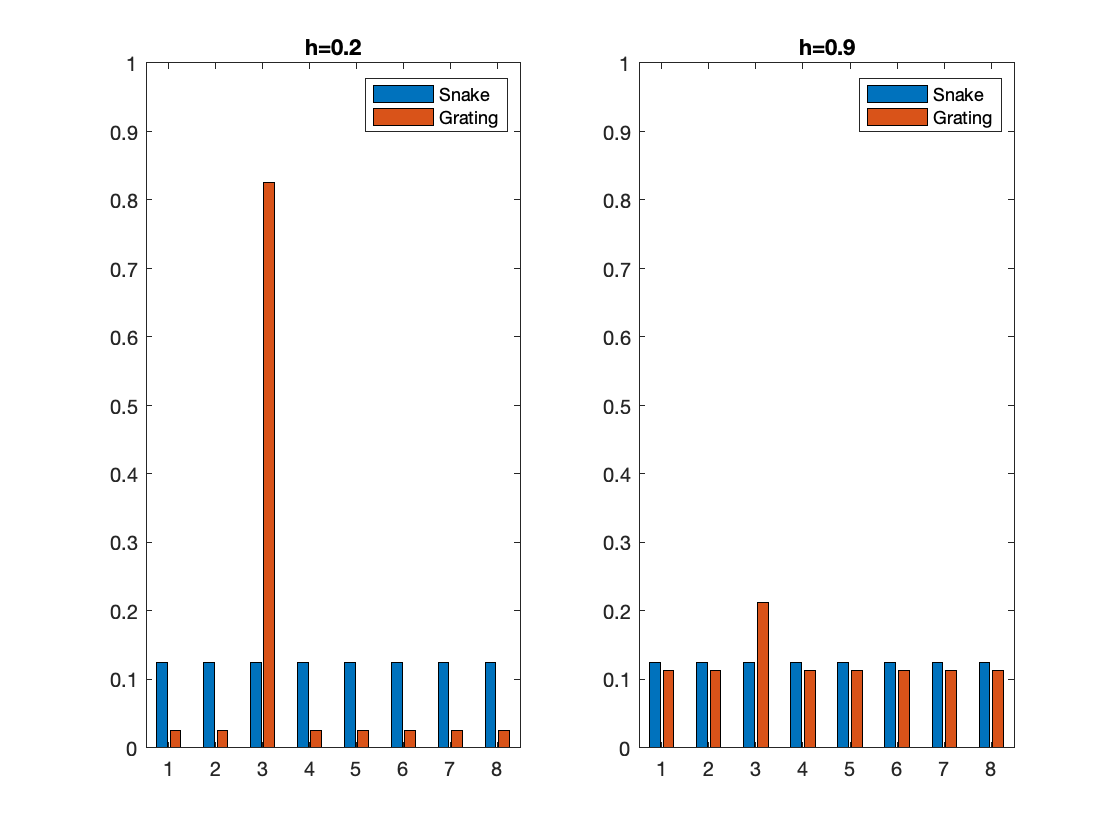

figure();
subplot(1, 2, 1)
h = .2; nT = 8;
E_Sna = ones(nT, 1)/nT;
E_Gra  = ones(nT, 1)*h/nT;
E_Gra(3) = 1 - h*(nT-1)/nT;
bar(1:nT, [E_Sna, E_Gra])
legend('Snake', 'Grating')
title(sprintf('h=%2g', h))
ylim([0,1])
subplot(1, 2, 2)
h = .9; nT = 8;
E_Sna = ones(nT, 1)/nT;
E_Gra  = ones(nT, 1)*h/nT;
E_Gra(3) = 1 - h*(nT-1)/nT;
bar(1:nT, [E_Sna, E_Gra])
legend('Snake', 'Grating')
title(sprintf('h=%2g', h))

ylim([0,1])

Then we pass two vectors through the following function


$$d(\theta) = \frac{E(\theta)}{1 + w E(\theta)} $$



$$s  = \frac{1}{N_{\theta}}\sum_\theta d(\theta)$$


The results suggest that normalization by contrast energy the gratings will always predict a lower response than the snakes. 

hs = linspace(.1, .9, 5); nH = length(hs);
ws = [.1, .5, 1, 3, 10];  nW = length(ws);

s_outcomes = nan(nW, nH, 2);
for i = 1:nW
    for j = 1:nH
        w = ws(i); h = hs(j);
        E_Sna = ones(nT, 1)/nT;
        d_Sna = E_Sna ./ (1 + w*E_Sna)
        s_Sna = mean(d_Sna);
        s_outcomes(i,j,1) = s_Sna;
        
        E_Gra  = ones(nT, 1)*h/nT;
        E_Gra(3) = 1 - h*(nT-1)/nT;
        d_Gra = E_Gra ./ (1 + w*E_Gra);
        s_Gra = mean(d_Gra);
        s_outcomes(i,j,2) = s_Gra;
    end
end

d_Sna =     0.1235
    0.1235
    0.1235
    0.1235
    0.1235
    0.1235
    0.1235
    0.1235


d_Sna =     0.1235
    0.1235
    0.1235
    0.1235
    0.1235
    0.1235
    0.1235
    0.1235


d_Sna =     0.1235
    0.1235
    0.1235
    0.1235
    0.1235
    0.1235
    0.1235
    0.1235


d_Sna =     0.1235
    0.1235
    0.1235
    0.1235
    0.1235
    0.1235
    0.1235
    0.1235


d_Sna =     0.1235
    0.1235
    0.1235
    0.1235
    0.1235
    0.1235
    0.1235
    0.1235


d_Sna =     0.1176
    0.1176
    0.1176
    0.1176
    0.1176
    0.1176
    0.1176
    0.1176


d_Sna =     0.1176
    0.1176
    0.1176
    0.1176
    0.1176
    0.1176
    0.1176
    0.1176


d_Sna =     0.1176
    0.1176
    0.1176
    0.1176
    0.1176
    0.1176
    0.1176
    0.1176


d_Sna =     0.1176
    0.1176
    0.1176
    0.1176
    0.1176
    0.1176
    0.1176
    0.1176


d_Sna =     0.1176
    0.1176
    0.1176
    0.1176
    0.1176
    0.1176
    0.1176
    0.1176


d_Sna =     0.1111
    0.1111
    0.1111
    0.1111
    0.1111
    0.1111
    0.1111
    0.1111


d_Sna =     0.1111
    0.1111
    0.1111
    0.1111
    0.1111
    0.1111
    0.1111
    0.1111


d_Sna =     0.1111
    0.1111
    0.1111
    0.1111
    0.1111
    0.1111
    0.1111
    0.1111


d_Sna =     0.1111
    0.1111
    0.1111
    0.1111
    0.1111
    0.1111
    0.1111
    0.1111


d_Sna =     0.1111
    0.1111
    0.1111
    0.1111
    0.1111
    0.1111
    0.1111
    0.1111


d_Sna =     0.0909
    0.0909
    0.0909
    0.0909
    0.0909
    0.0909
    0.0909
    0.0909


d_Sna =     0.0909
    0.0909
    0.0909
    0.0909
    0.0909
    0.0909
    0.0909
    0.0909


d_Sna =     0.0909
    0.0909
    0.0909
    0.0909
    0.0909
    0.0909
    0.0909
    0.0909


d_Sna =     0.0909
    0.0909
    0.0909
    0.0909
    0.0909
    0.0909
    0.0909
    0.0909


d_Sna =     0.0909
    0.0909
    0.0909
    0.0909
    0.0909
    0.0909
    0.0909
    0.0909


d_Sna =     0.0556
    0.0556
    0.0556
    0.0556
    0.0556
    0.0556
    0.0556
    0.0556


d_Sna =     0.0556
    0.0556
    0.0556
    0.0556
    0.0556
    0.0556
    0.0556
    0.0556


d_Sna =     0.0556
    0.0556
    0.0556
    0.0556
    0.0556
    0.0556
    0.0556
    0.0556


d_Sna =     0.0556
    0.0556
    0.0556
    0.0556
    0.0556
    0.0556
    0.0556
    0.0556


d_Sna =     0.0556
    0.0556
    0.0556
    0.0556
    0.0556
    0.0556
    0.0556
    0.0556


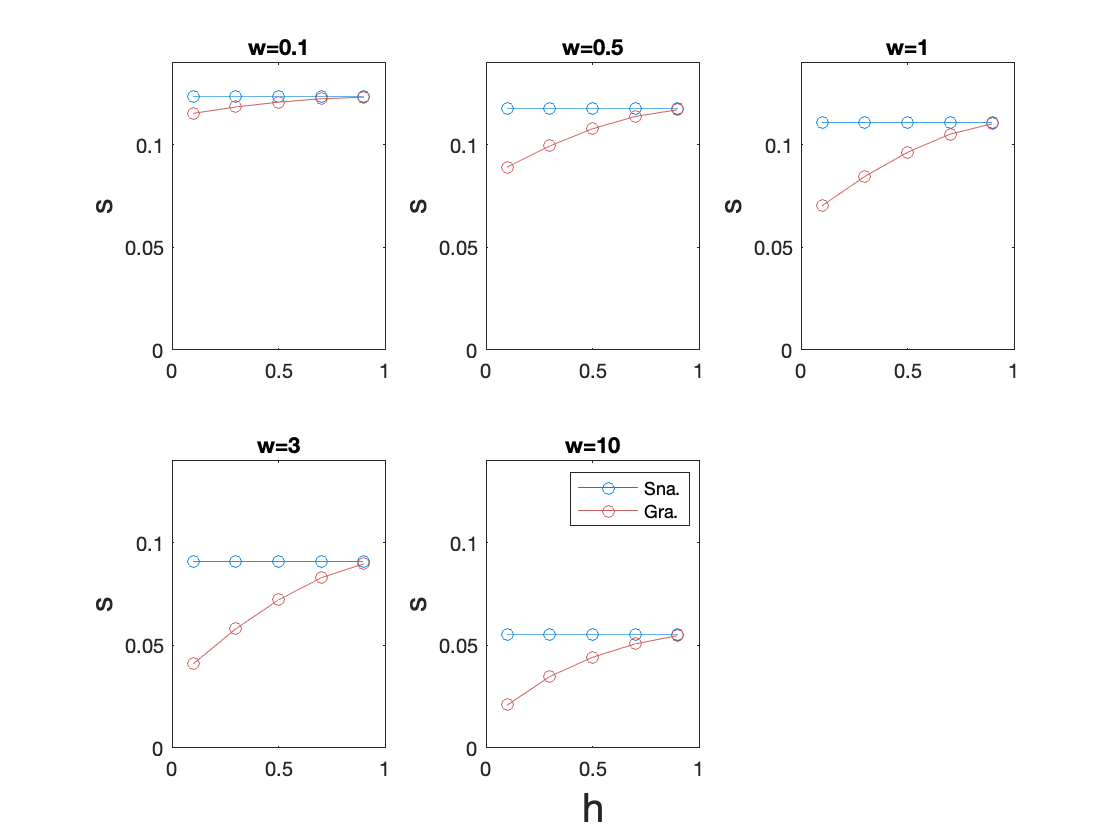


figure; 
for i = 1:nW
    subplot(2, 3, i)
    plot(hs, s_outcomes(i, :, 1), ...
        'o-', 'Color', viz.Blue)
    hold on 
    plot(hs, s_outcomes(i, :, 2), ...
        'o-', 'Color', viz.Red)
    ylim([0, .14])
    ylabel('s', "FontSize", 15)
    title(sprintf('w=%g', ws(i)))
end
legend('Sna.', 'Gra.')
xlabel('h', 'FontSize', 20)

hold off 

## The NCE is good

## Performance in the target data set

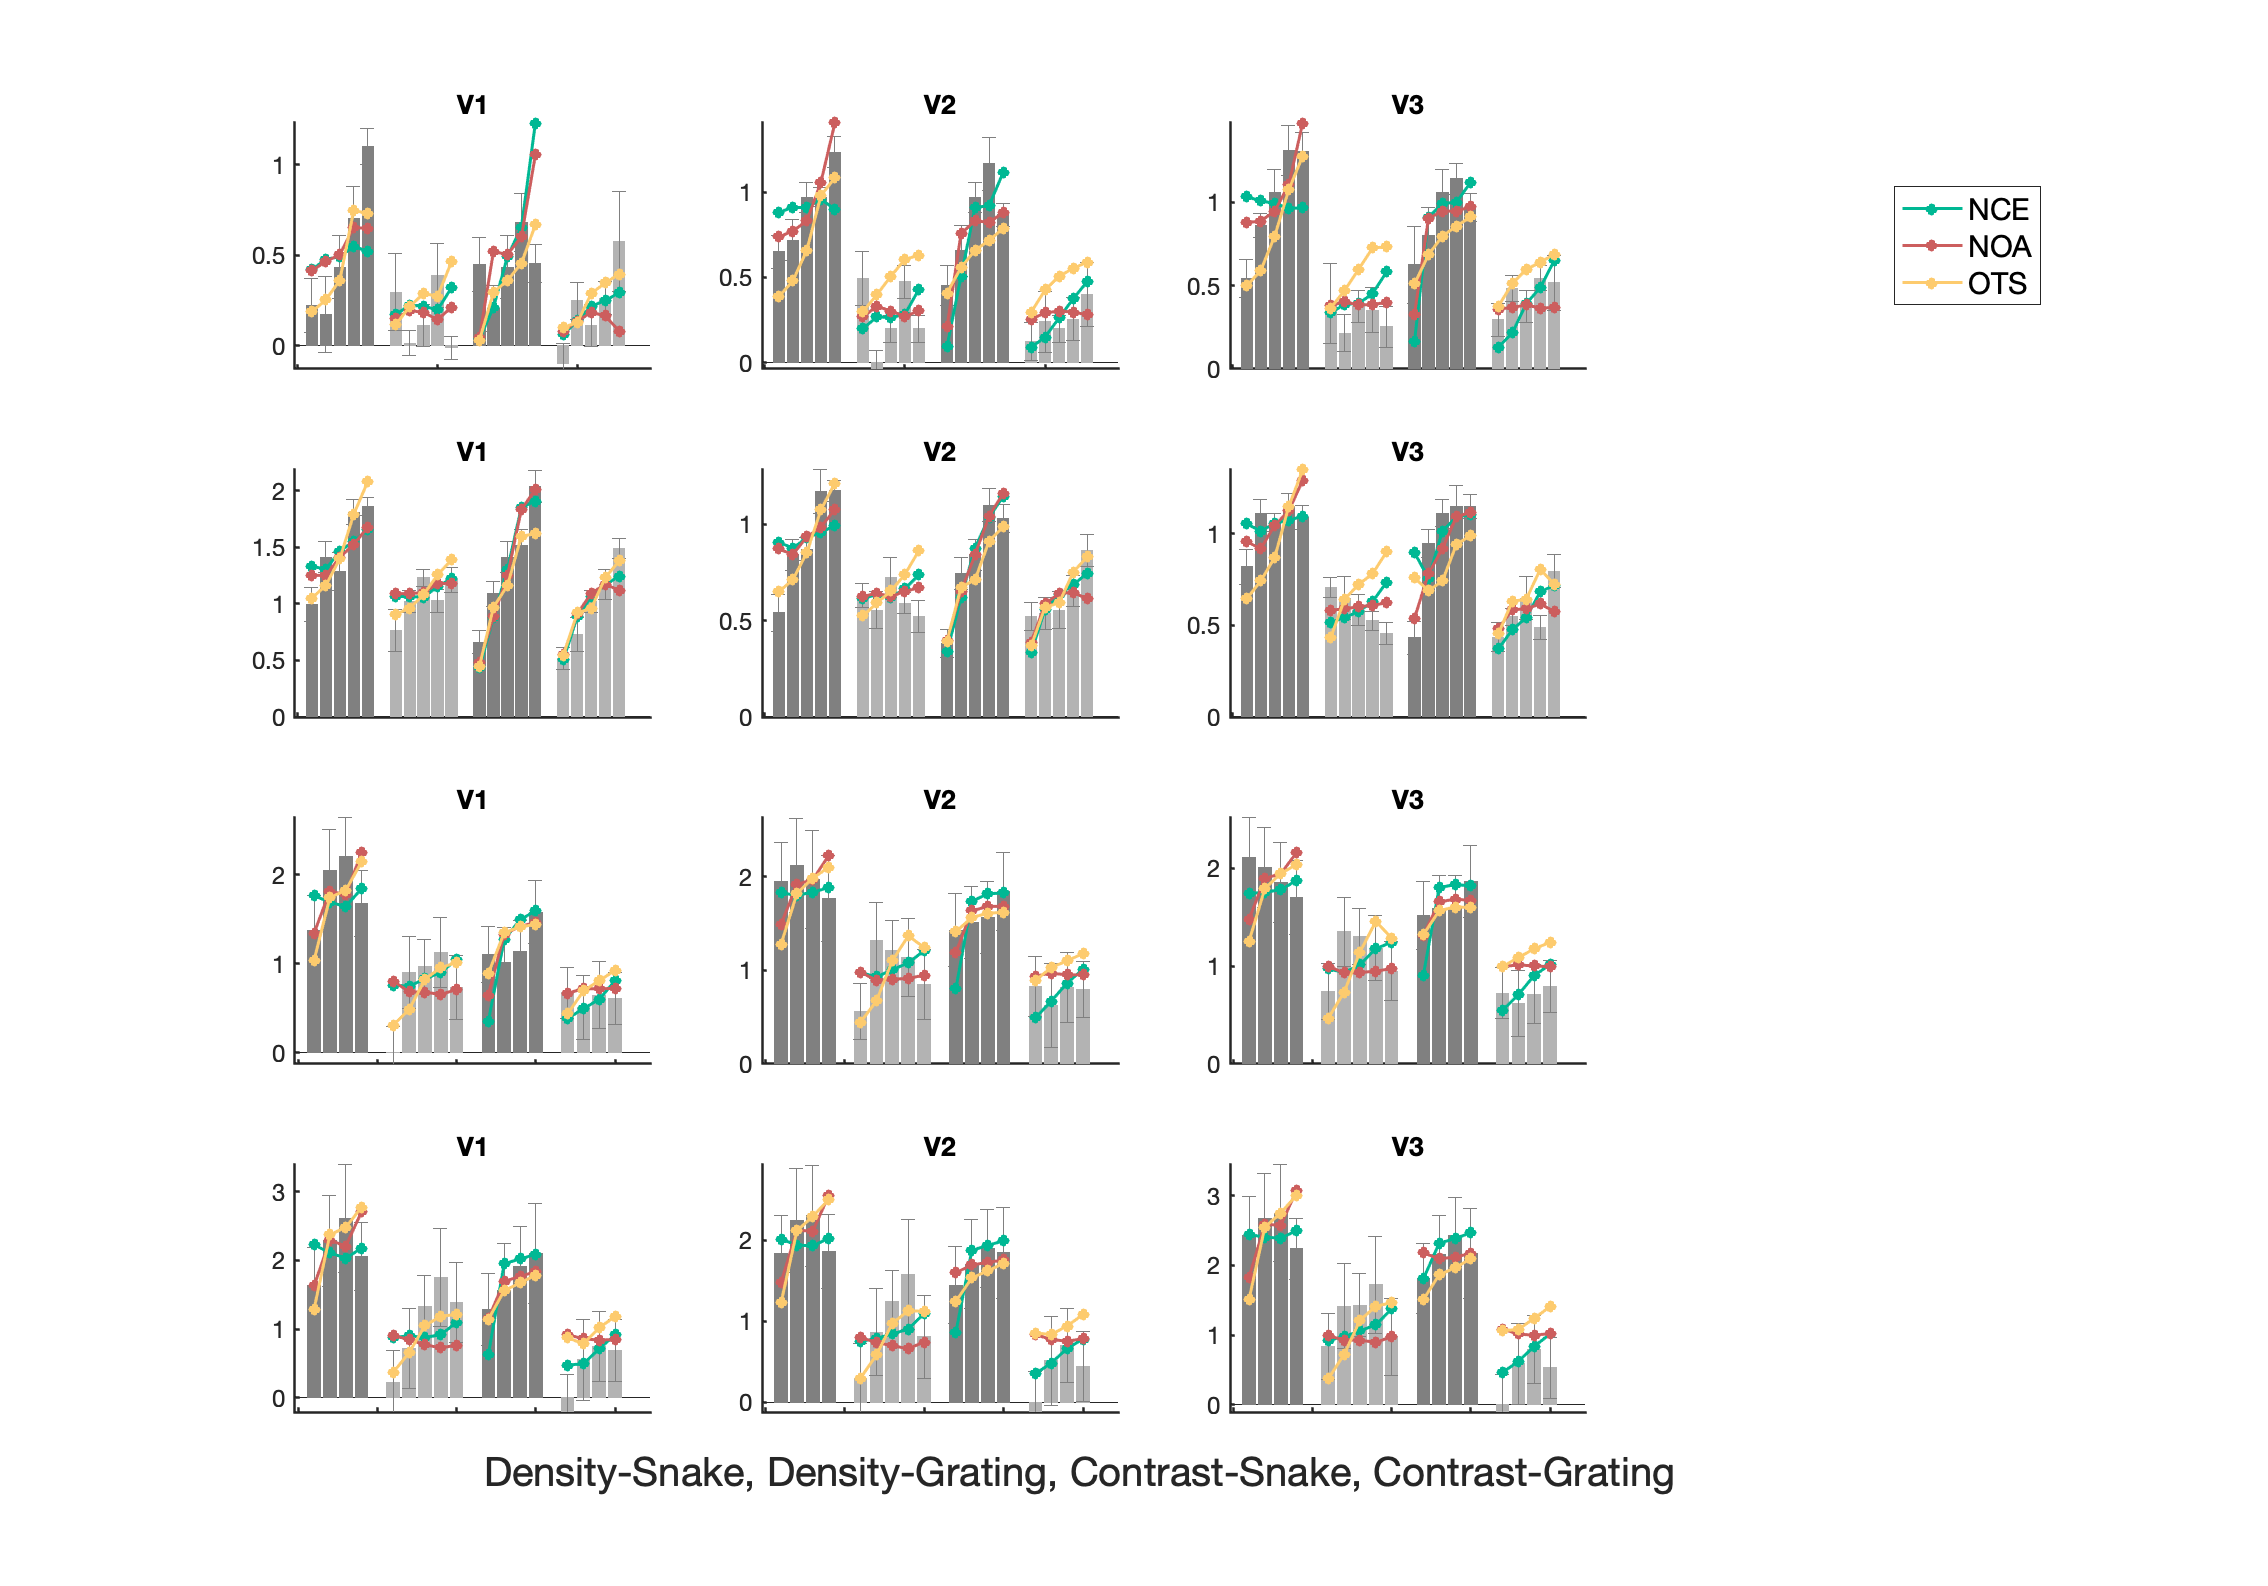

fig = figure();
s4_visualize('Ori_Model')
han=axes(fig,'visible','off'); 
han.XLabel.Visible='on';
xlabel(han,'Density-Snake, Density-Grating, Contrast-Snake, Contrast-Grating                 ', "FontSize", 20);

## Performance on data set 1, all stimuli 

See the arxiv for the x label.

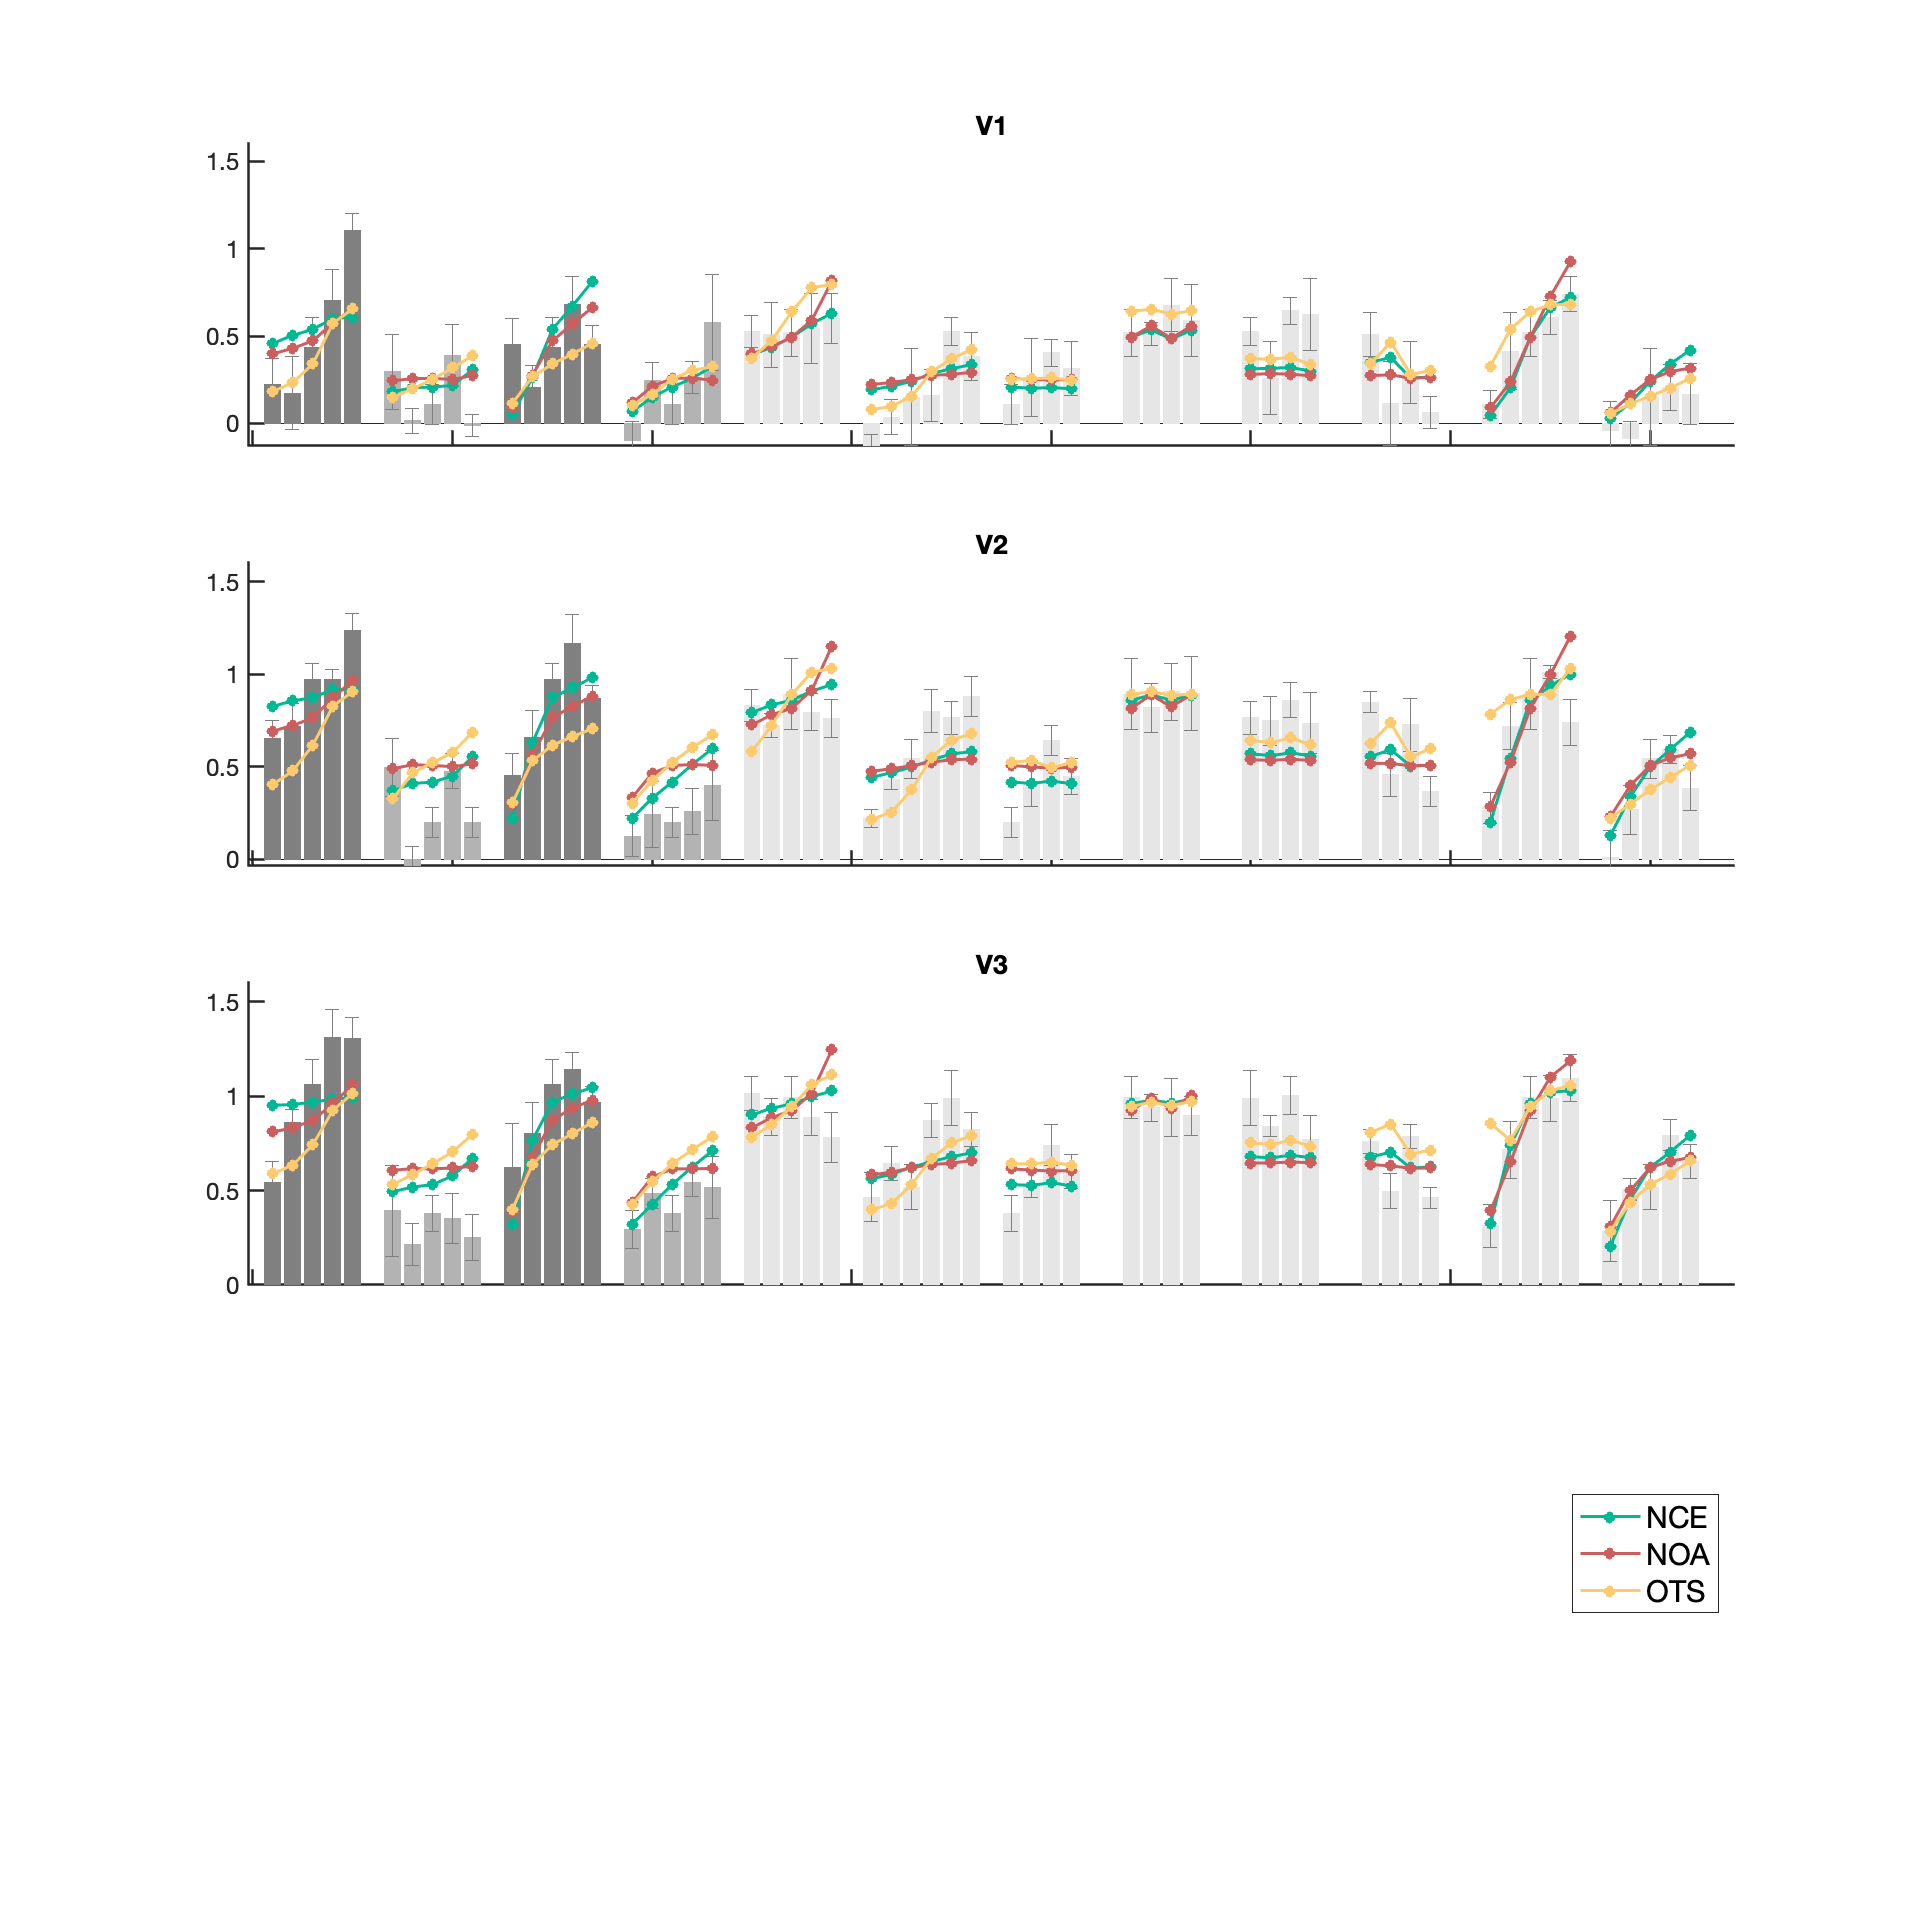

fig = figure();
s4_visualize('figureS8a')

## Performance on data set 2, all stimuli 

See the arxiv for the x label.

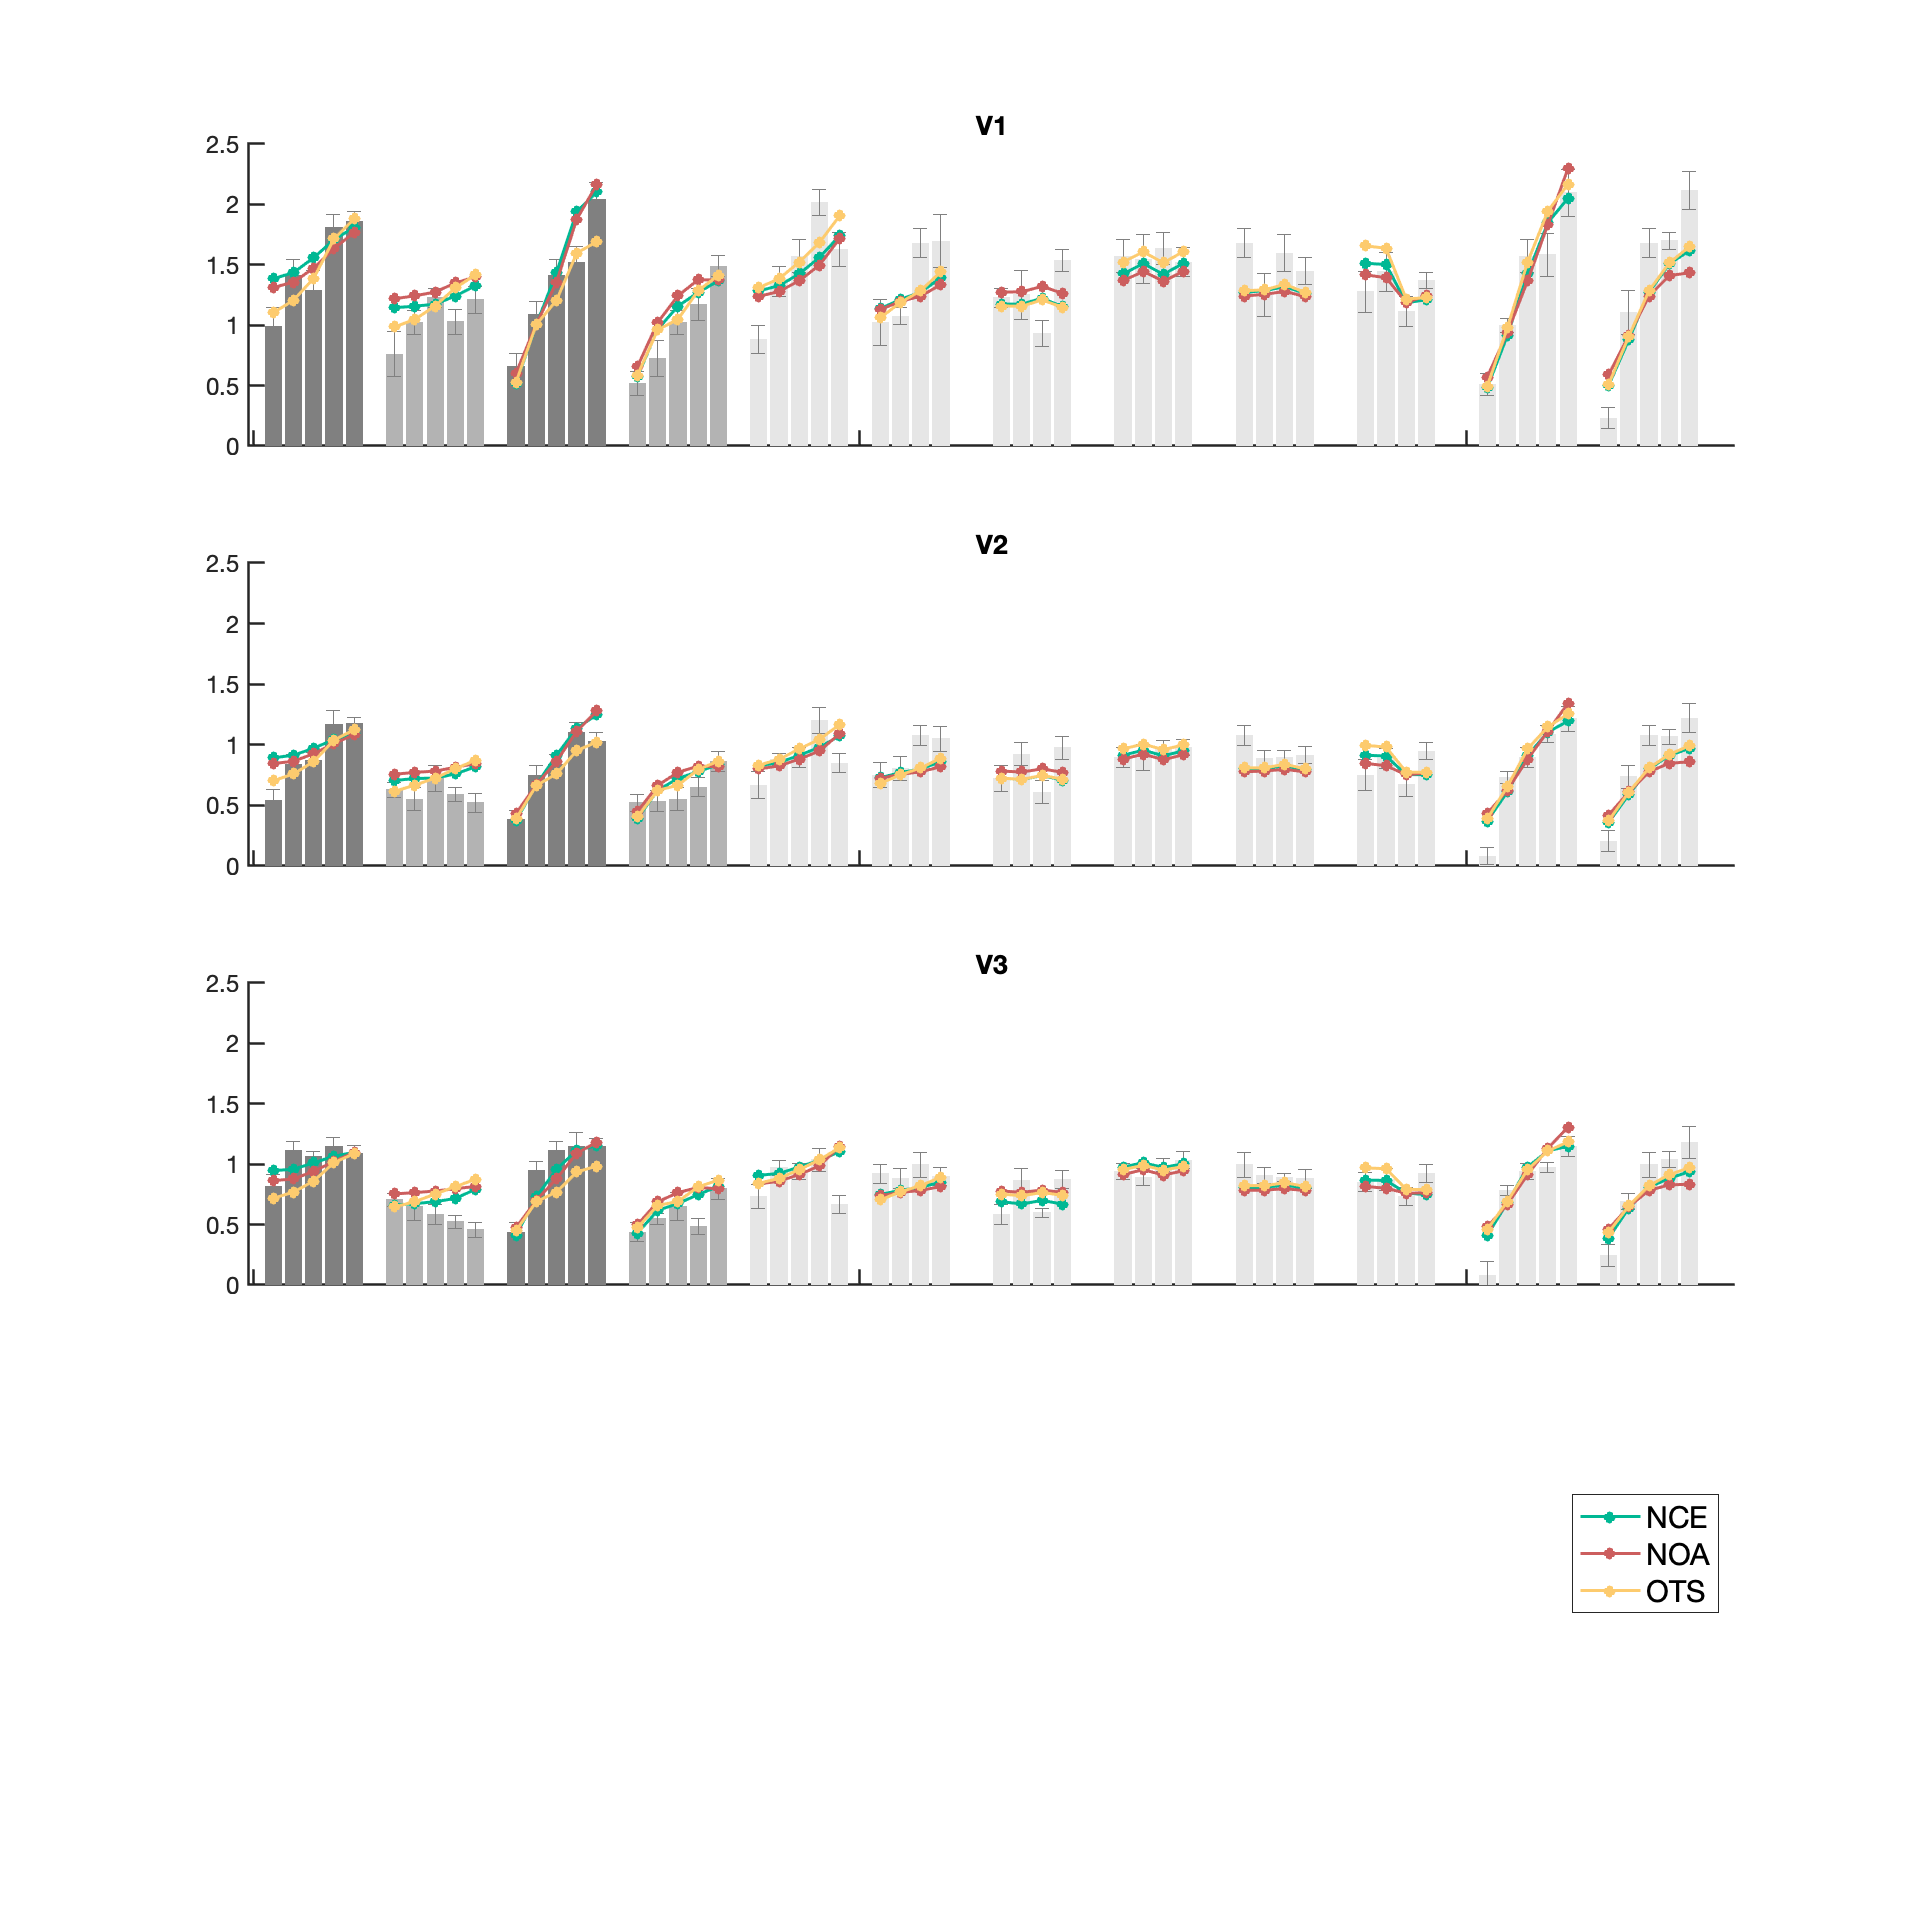

fig = figure();
s4_visualize('figureS8b')

## Performance on data set 3, all stimuli 

See the arxiv for the x label.

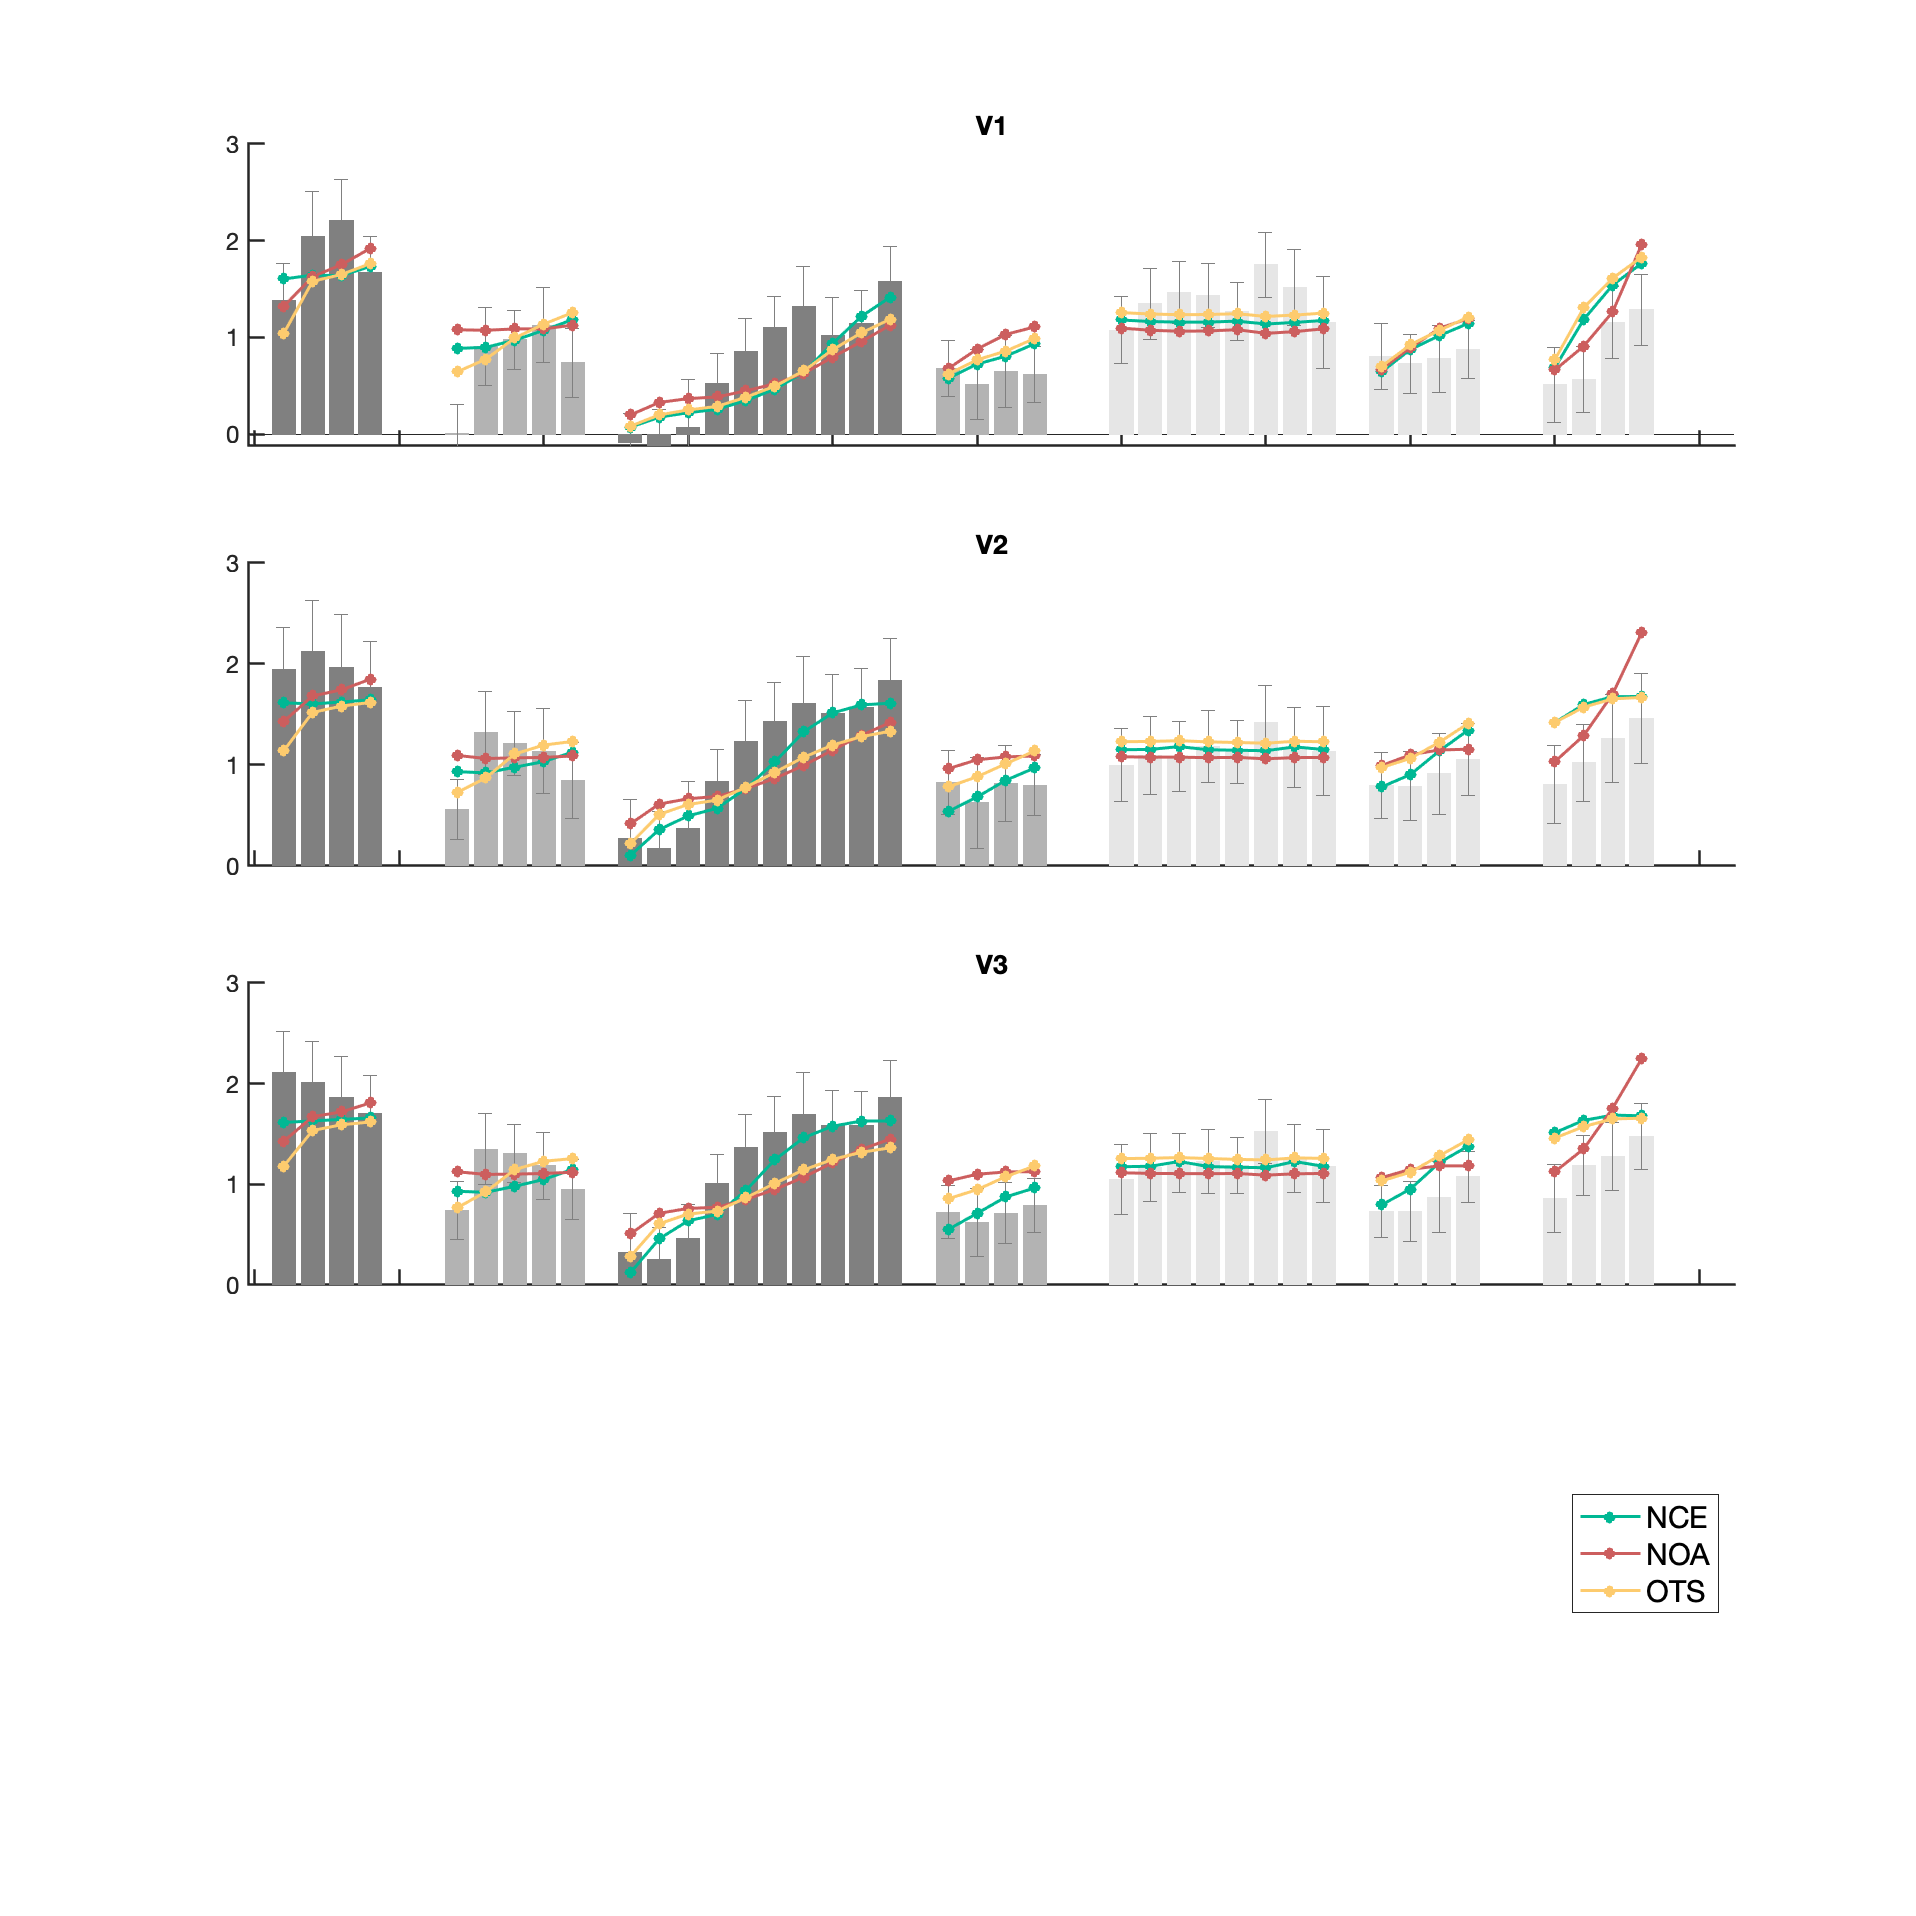

fig = figure();
s4_visualize('figureS8c')

## Performance on data set 4, all stimuli 

See the arxiv for the x label.

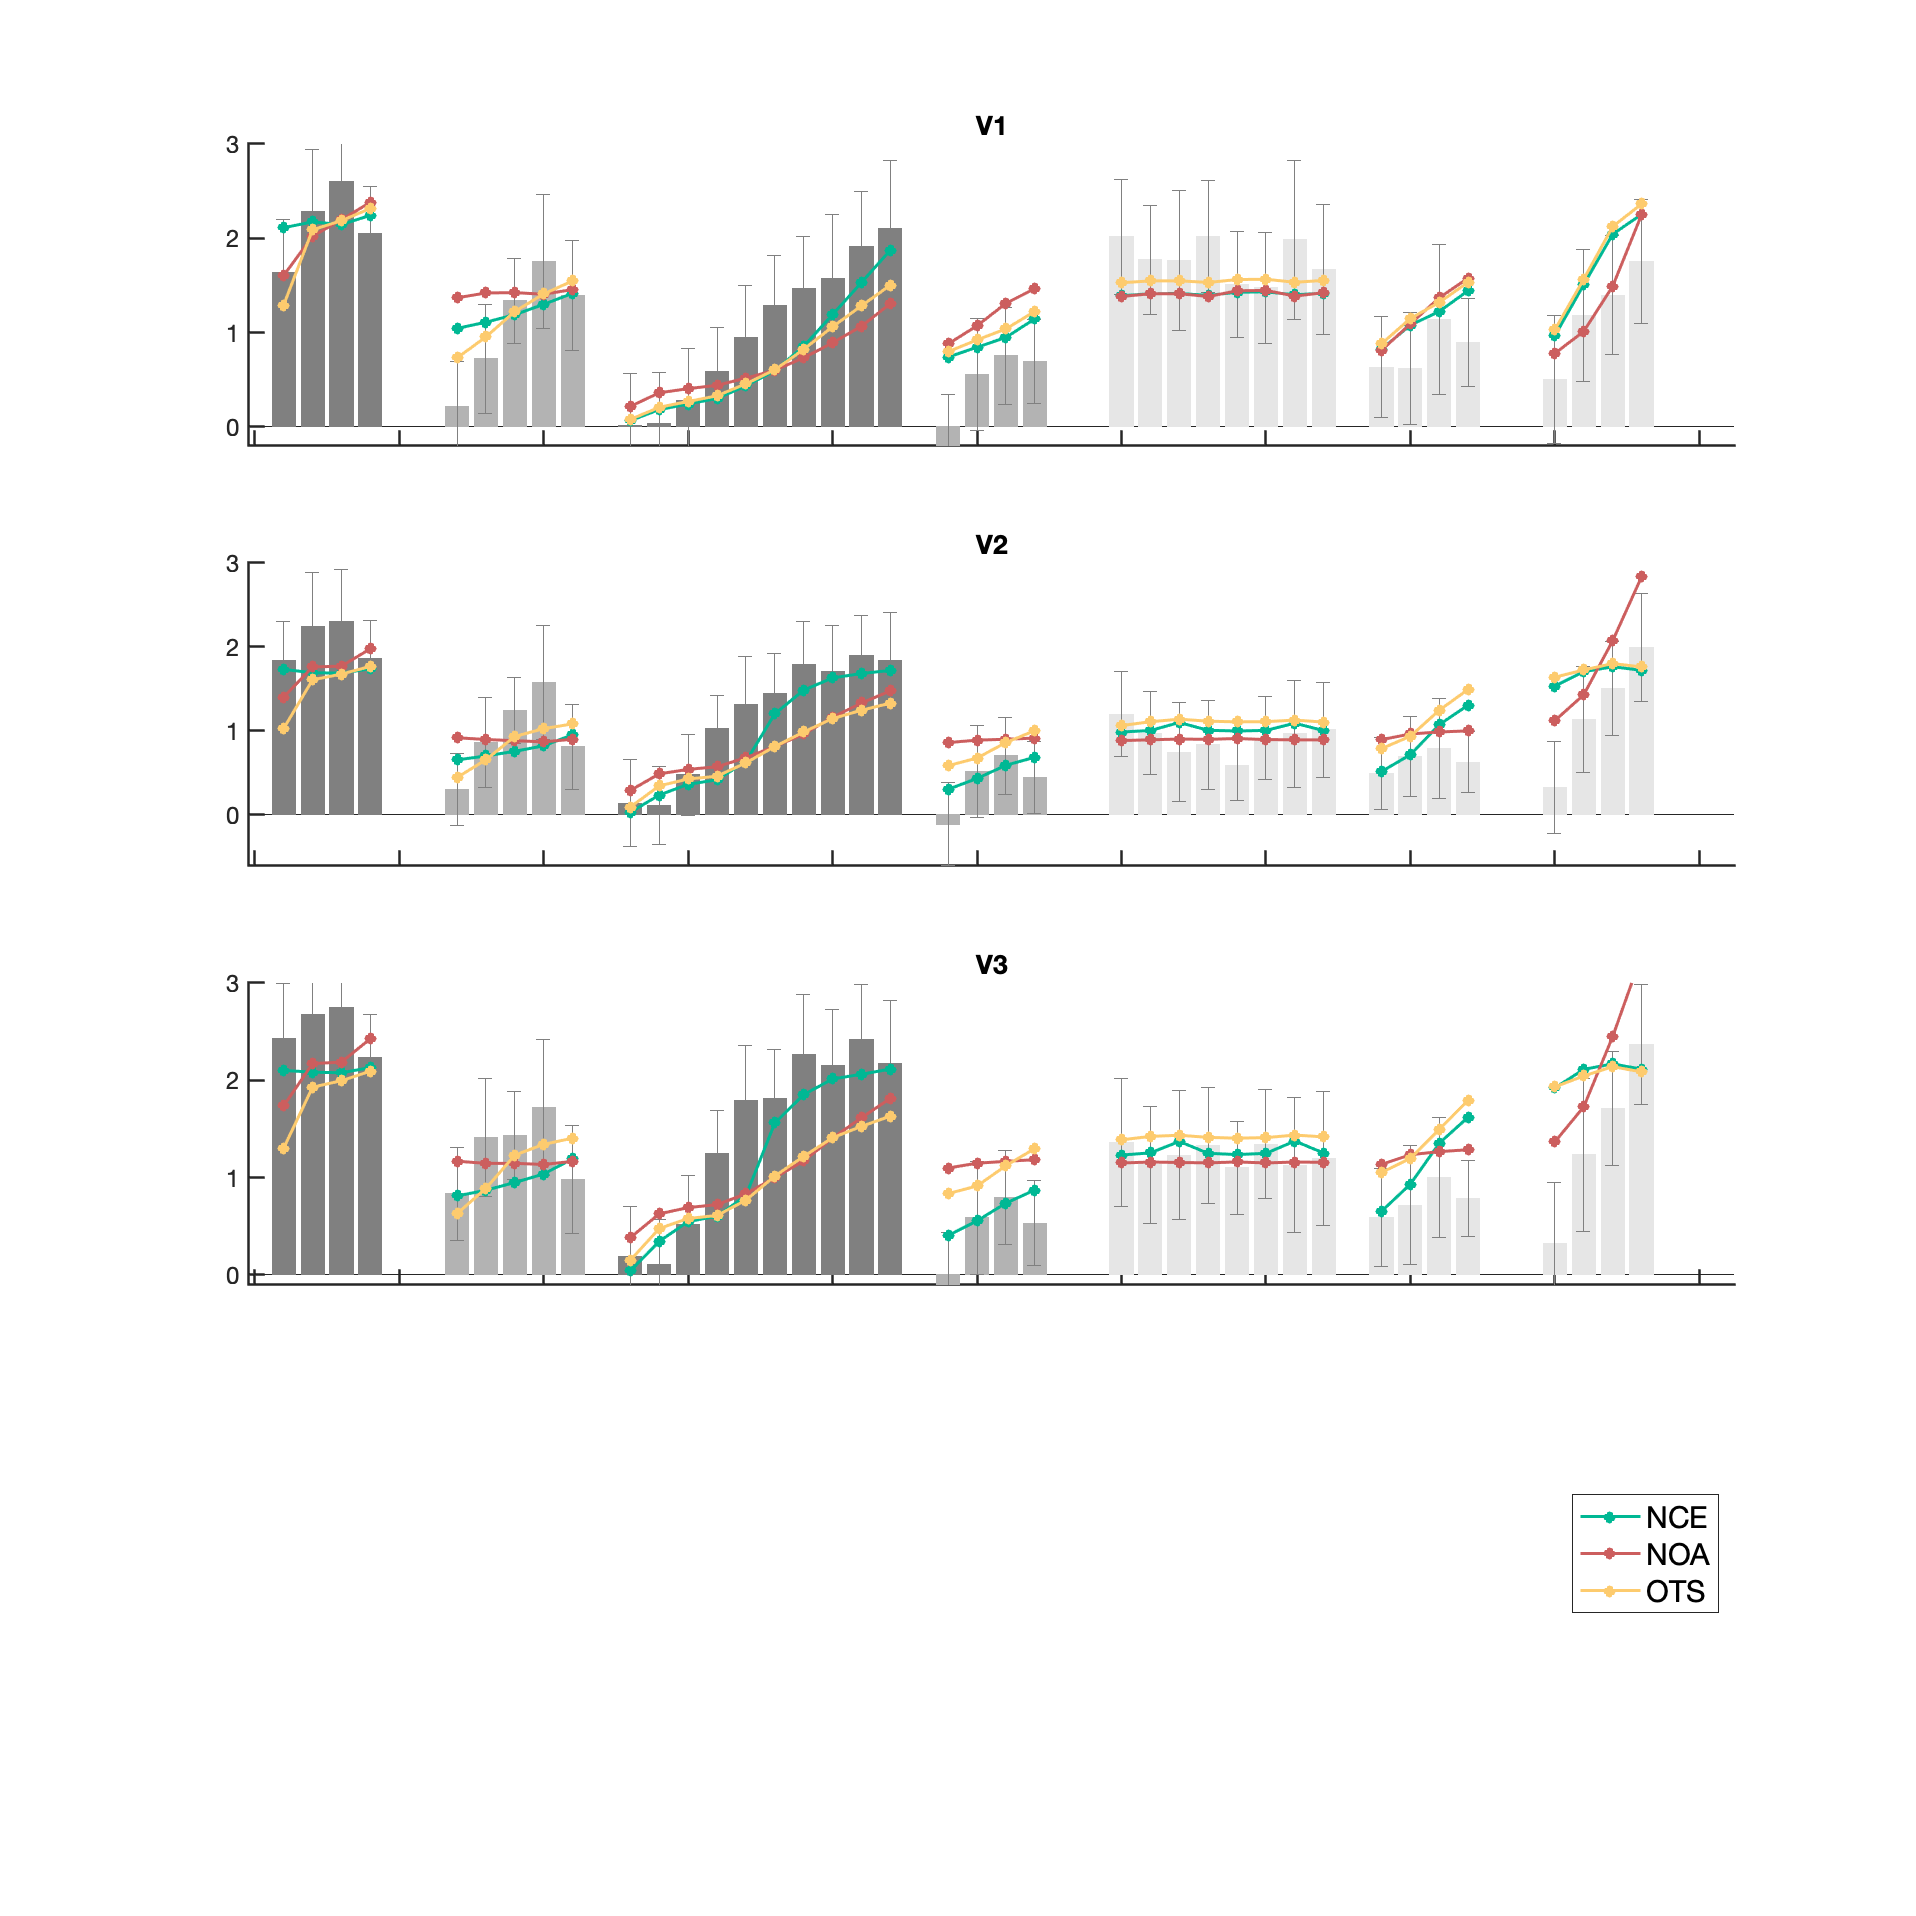

fig = figure();
s4_visualize('figureS8d')

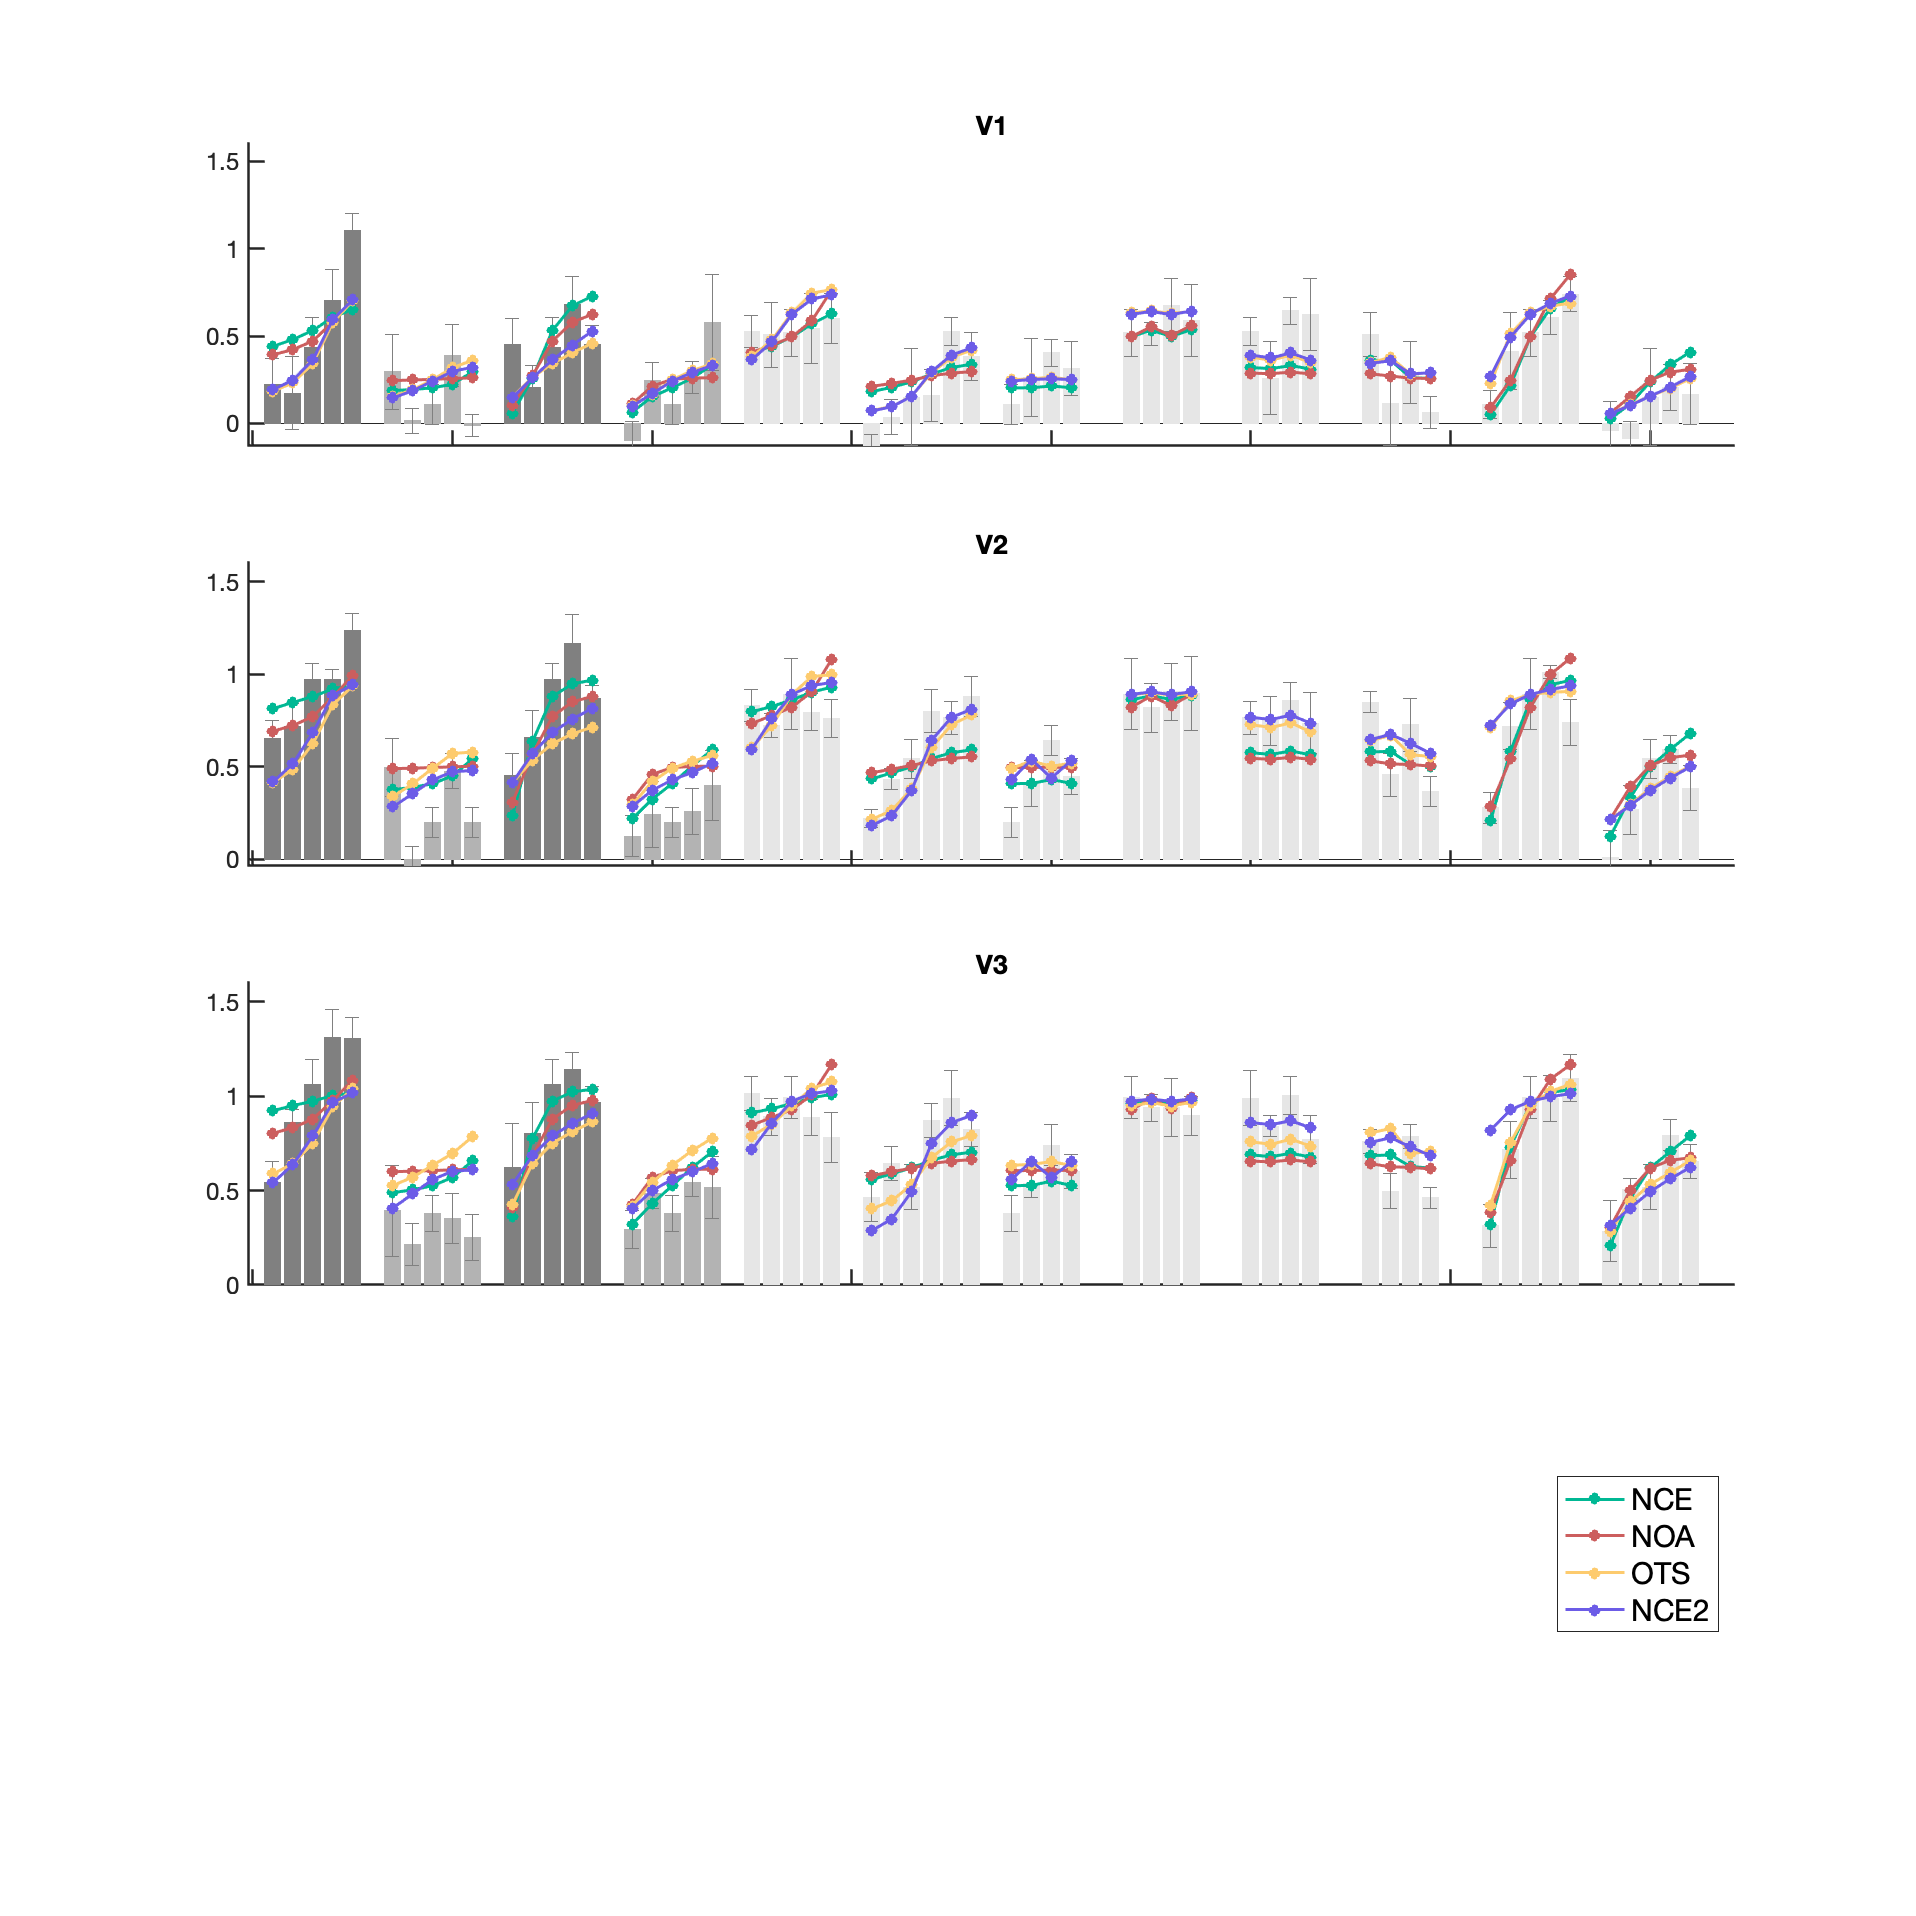

figure();
s4_visualize('all-noCross-m2m3m5m6-ds1')